# **The emergence of hippocampal 4-Hz oscillations during wheel running**

Ivan Alisson Cavalcante Nunes de Lima and Hindiael Belchior

## **Abstract (250 words maximum) scope, novelty, and significance** 

Recent studies have shown oscillatory activity in the delta band frequency during running, but little is currently known about its underlying mechanisms.

Here we report the emergence of a 4-Hz oscillation in the CA1 LFP of rats running in a wheel that was essentially absent during running through a maze. The instantaneous 4-Hz amplitude and frequency positively correlated with running speed in the wheel but not in the maze. Hippocampal 4-Hz oscillations were resistant to pharmacological inactivation of the medial septum, while theta oscillations were abolished. These results dissociate the underlying mechanism of 4-Hz and theta oscillations in the hippocampus. 

Keywords: 4-Hz oscillations, hippocampus, medial septum inactivation, locomotion

## **HIGHLIGHTS**

- 4-Hz oscillations emerge in the rat hippocampus during wheel running

- Hippocampal 4-Hz amplitude and frequency correlate with running speed

- Hippocampal 4-Hz oscillations are resistant to medial septum inactivation 

## **IN BRIEF**

Lima and Belchior show that  4-Hz oscillations emerge in the rat hippocampus during stationary running on a wheel but not on the maze. 4-Hz oscillations are not dependent on septal inputs like theta oscillations.

## **GRAPHICAL ABSTRACT**

## **INTRODUCTION**

Locomotor activity modulates theta (6-10 Hz) oscillations in the rat hippocampus, which are strongly correlated by running speed. However, recent studies have shown that oscillatory activity in the delta (1-4 Hz) band is also associated with running speed in stationary conditions. 

While the former are modulated by running speed, the latter is maintained relatively constant. In our experiment, systematic changes in running speed resulted in consistent changes in 4-Hz power and frequency, following changes in interoceptive signals. Whether the major influences over hippocampal delta oscillations are due to self-motion cues or other physiological responses to running exercise remains to be further investigated.

Stationary running is fundamentally different from translational locomotion in the environment because it decouples afferent inputs derived from the body's internally and externally generated signals (Terrazas and McNaughton, 2005). While changes in proprioceptive signals follow changes in the internal metabolism, exteroceptive sensory signals (e.g., olfactive and visual landmarks) from the environment are maintained relatively constant. The respiratory rhythms, for instance, may shift from stimulus-induced sniffing activity to predominantly periodic breathing when rats abandon translational locomotion to engage in stationary running (ref). Changes in respiratory rhythms have been recently correlated with changes in hippocampal oscillation within the 1-10 Hz frequency range (Tort., 2018). We thus hypothesize that the rising of hippocampal delta oscillations during stationary runs may be related to respiratory signals that are concomitantly entrained by running activity. Future studies that simultaneously monitor breathing and hippocampal activity during stationary runs will be necessary to test this hypothesis. 

## **METHODS**

The dataset used in this study was previously acquired at the Pastalkova Lab on the Janelia Research Campus (Wang et al., 2014) and made available at [http://datadryad.org/](http://datadryad.org/) under public domain dedication license. 

### **Behavioral and electrophysiological recordings**

Two 64-channel linear silicon probes (Neuronexus or Janelia RC) were bilaterally implanted at the dorsal CA1 area (coordinates: -4.0 mm AP, ± 3 mm ML) of the rat hippocampus (n = 3 animals across ten sessions). Local field potentials, spiking activity, and digital video recordings were obtained during a delayed spatial alternation memory task in a U-shaped maze coupled to a wheel in which animals ran (~15 s) during the intertrial intervals. Electrophysiological and behavioral recordings were obtained before (n = 304 trials) and after (n = 501 trials) muscimol microinjections into the medial septum. Detailed experimental procedures can be found in previous publications (Wang et al., 2014).

### **Data analysis**

All data analyses were custom made and built-in routines in MATLAB. We excluded trials in which electrophysiological data presented electrical or movement artifacts of our analysis. Recordings were notch-filtered between 55 Hz and 65 Hz to remove 60 Hz electrical noise. LFP signals larger than two times the standard deviation were removed from three sessions of one animal (rat 943) due to movement artifacts. 

We then used the **“eegfilt”** function (EEGLAB Toolbox, [Delorme and Makeig, 2004)](https://www.zotero.org/google-docs/?PeKQqH) to obtain delta (3-5 Hz) and theta (6-10 Hz) components of the LFP signals. The **“pwelch”** function from the Signal Processing Toolbox to obtain the power spectral density (PSD). The **“hilbert”** function from the Signal Processing Toolbox to obtain the instantaneous delta and theta band amplitude, phase, and posteriorly, instantaneous frequency. The **“xcorr”** function (0.5-s window length, option type “coeff”) from the Signal Processing Toolbox. We used the **“spectrogram”** function (2-s window length with 90% overlap) from the Signal Processing Toolbox to obtain the time-frequency decomposition. The **“corr”** function (option type “Spearman”) from the Signal Processing Toolbox to obtain the correlation coefficients between running speed and the instantaneous amplitude and frequency at the delta and theta bands (5-s time windows). We used the **Shapiro-Wilk** test to evaluate data normality. **Wilcoxon rank-sum test** to compare between maze and wheel running conditions, and between wheel running previous to correct and incorrect choices and **Wilcoxon signed-rank **test was used to compare between wheel running pre and post muscimol injections. 

% A - Load scripts and project folder

clear
clc
close all
format compact
cd('D:/Ivan/OneDrive/Projetos/Códigos ( Profissional )/Material criado/ICE/Proj_BSc_Hippocampus_Delta_Analysis');
addpath('Routines/Functions/');
srate=1250;
dt=1/srate;

% B - Pre process
% Load database, select desired attributes, filter noise, calculate pwelch,
% eeg and hilbert
% Track: eeg, speed_MMsec, lapID
% Laps: WhlSpeedCCW, WhlSpeedCW
% Spike: cluu, res
% Clu: isIntern
% 
% 1 - Load and filter files

% Ignored files ...
%
% Files source path
dbPathOne = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part1~/';
dbPathTwo = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part2~/';

% List of paths
filePaths = [dbPathOne; dbPathTwo];

% Pwelch - Specifications
WindowLength = 1*srate;
Overlap      = 0.9*srate;
NFFT         = 2^13;

% order = [0; 1];
tittles = "All_Combined";
wSpeed = 100;
mSpeed = 100;

savePath = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/Processed/Single Files/';

% Change to 1 if yout want to process all files and create the data ( 1st
% time )
processFiles = 0;
% Load files
if processFiles
    for i=1:size(filePaths,1)
        % List all files in each directory
        absolutFilePath = ls(fullfile(filePaths(i,1:end), '*.mat'));
        % Get the number of files
        [numFil, ~ ] = size(absolutFilePath);

        % Load each .mat in the structure
        for j=1:numFil
            dataSingle = load(strcat(filePaths(i,1:end),absolutFilePath(j, 1:end)), 'Track', 'Laps', 'Clu', 'Spike');

            % Select desired attributes
            trackNames = fieldnames(dataSingle.Track);
            trackNames(find(strcmp(trackNames, 'eeg'))) = [];
            trackNames(find(strcmp(trackNames, 'speed_MMsec'))) = [];
            trackNames(find(strcmp(trackNames, 'lapID'))) = [];
            trackNames(find(strcmp(trackNames, 'corrChoice'))) = [];
            lapsNames = fieldnames(dataSingle.Laps);
            lapsNames(find(strcmp(lapsNames, 'WhlSpeedCW'))) = [];
            lapsNames(find(strcmp(lapsNames, 'NLapCW'))) = [];
            spikeNames = fieldnames(dataSingle.Spike);
            spikeNames(find(strcmp(spikeNames, 'totclu'))) = [];
            spikeNames(find(strcmp(spikeNames, 'speed_MMsec'))) = [];
            spikeNames(find(strcmp(spikeNames, 'whlSpeed'))) = [];
            spikeNames(find(strcmp(spikeNames, 'res'))) = [];
            cluNames = fieldnames(dataSingle.Clu);
            cluNames(find(strcmp(cluNames, 'isIntern'))) = [];
            
            dataSingle.Track = rmfield(dataSingle.Track,trackNames);
            dataSingle.Laps = rmfield(dataSingle.Laps,lapsNames);        
            dataSingle.Spike = rmfield(dataSingle.Spike,spikeNames);  
            dataSingle.Clu = rmfield(dataSingle.Clu,cluNames);  
            dataSingle.Name = absolutFilePath(j, 1:16);

            % Save unmodified LFP
            dataSingle.Track.origEeg = dataSingle.Track.eeg;
            % Filter noise
            dataSingle = filterLFP(dataSingle, srate);
            
            % Process ( Pwelch, hilbert, eeg )
            dataSingle = fillStruct(srate, WindowLength, Overlap, NFFT, dataSingle, wSpeed, mSpeed);

            Spike = dataSingle.Spike;
            Name = dataSingle.Name;
            Clu = dataSingle.Clu;  
            Lfp = dataSingle.Lfp;
            Delta = dataSingle.Delta;
            Theta = dataSingle.Theta;
            Choice = dataSingle.Choice;
            Speed = dataSingle.Speed;
            Pwelch = dataSingle.Pwelch;
            % Save
            mmtTtl = 'Pre';
            if i == 2
                mmtTtl = 'Pos';
            end

            file = sprintf('%s%s/%s/%s.mat', savePath, tittles, mmtTtl, Name);
            save(file, 'Clu', 'Spike', 'Name', 'Pwelch', 'Lfp', 'Delta', 'Theta', ...
               'Choice', 'Speed', '-v7.3')  

            sprintf('Dir: %d, File: %d', i, j)
        end
    end
end
clearvars -except srate dt Band Clu Name Spike

% C - Load processed file ( if the data was previously created, start here to continue analysis )
% 1 - Load files. Filtered data, with pwelch and eegfilt
tic
clear
clc
close all
format compact
cd('D:/Ivan/OneDrive/Projetos/Códigos ( Profissional )/Material criado/ICE/Proj_BSc_Hippocampus_Delta_Analysis');
addpath('Routines/Functions/');
srate=1250;
dt=1/srate;

rootPath = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/Processed/Single Files/';
subPath = ["All_Combined"];
idx = 1;
loadPath = sprintf('%s%s/', rootPath, subPath(idx));

% Load files
dataFull = {};
% Load Pre
absolutFilePath = ls(fullfile(sprintf('%sPre/', loadPath), '*.mat'));
for file=1:size(absolutFilePath, 1)
    fileName = absolutFilePath(file, :);
    dataFull{1, file} = load(strcat(loadPath, 'Pre\', fileName));
%     sprintf('%s - Pre - File: %d', subPath(idx), file)
end
% Load Pos
absolutFilePath = ls(fullfile(sprintf('%sPos/', loadPath), '*.mat'));
for file=1:size(absolutFilePath, 1)
    fileName = absolutFilePath(file, :);
    dataFull{2, file} = load(strcat(loadPath, 'Pos\', fileName));
%     sprintf('%s - Pos - File: %d', subPath(idx), file)
end
[numReads, numSubReads ] = size(dataFull);
clearvars -except dataFull srate dt numReads numSubReads 
toc

Elapsed time is 45.755600 seconds.


## **RESULTS **

### **4-Hz oscillations emerge in the rat hippocampus during wheel running**

Rats were trained to perform a delayed spatial alternation task on a U-shaped maze and run for 15 s on a wheel during the inter-trial intervals (Figure 1A). Local field potential (LFP) and spiking activity were recorded from the CA1 area of the dorsal hippocampus of three rats (805 trials across 10 sessions). Consistent with previous reports, spectral decomposition of CA1 LFP showed prominent theta (6-10 Hz) oscillations while rats ran throughout the maze and on the wheel (Figure 1B, left and right, respectively). Interestingly, however, only running on the wheel further exhibited remarkable rhythmicity at a slower frequency around 4 Hz. Hippocampal 4-Hz oscillations were noticeable at the raw LFP signals and spectrograms during wheel running but not at maze runs in trials with similar running speeds (Figure 1B and Supplementary Figure X). Autocorrelograms revealed strong rhythmicity during maze and wheel running with interpeak intervals of 145 ms (6.8 Hz) and 320 ms (3.1 Hz), respectively (Figure 1C). Averaged power spectra at the group level show a single peak at 8.7 Hz during maze running and two peaks at 7.8 Hz and at 4 Hz at the wheel (Figure 1D). 4-Hz band power was significantly higher during wheel runs than at maze runs (Figure 1E, left, p < 0.01, Wilcoxon signed-rank test). Theta peak power was also higher at the wheel (Figure 1E, right, p < 0.01, Wilcoxon signed-rank test), while theta peak frequency was significantly slower at the wheel than at the maze (Supplementary Figure X, p<0.01, Wilcoxon signed-rank test).

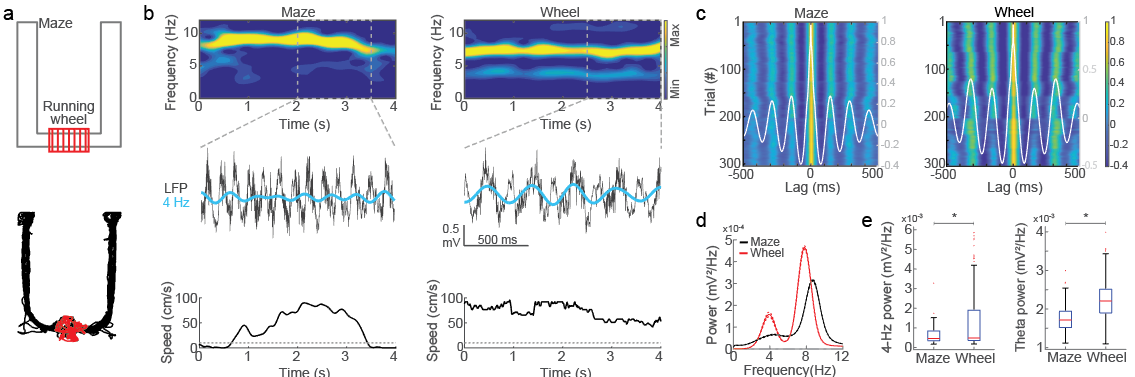

**Figure 1 - Hippocampal 4-Hz oscillations emerge during wheel running, but not maze running. (A) **Schematic representation of the U-shaped maze (gray) coupled to a running wheel (red, upper). A typical example of the spatial trajectory of a rat on the maze (black) and on the wheel (red, lower).** (B) **Spectrograms showing energy at 0-12 Hz frequencies during representative maze and wheel runs (left and right, respectively, upper). Notice that only the wheel running exhibits prominent energy at 4 Hz and 8 Hz frequencies. Raw LFP and 3-5 Hz band-filtered signals (gray and cyan, respectively, middle), and the instantaneous running speed at the same maze and wheel runs as above (lower). (**C)** Autocorrelograms of LFP signals across 304 runs at the maze and the wheel (left and right, respectively). Gray traces represent the average autocorrelograms across trials. Interpeak intervals were 145 ms (6.8 Hz) during maze runs and 320 ms (3.1 Hz) during wheel runs. (**D) **Average power spectra from LFP obtained during maze and wheel runs (black and red, respectively, n=304 trials). Solid lines depict mean and dashed lines depict ± SEM. (**E)** Boxplot showing the distribution of power at the 3-5 Hz band during maze and wheel runs (left, p < 0.01, Wilcoxon signed-rank test). Distribution of power at the theta (6-10 Hz) band during maze and wheel runs (right, p < 0.01, Wilcoxon signed-rank test).

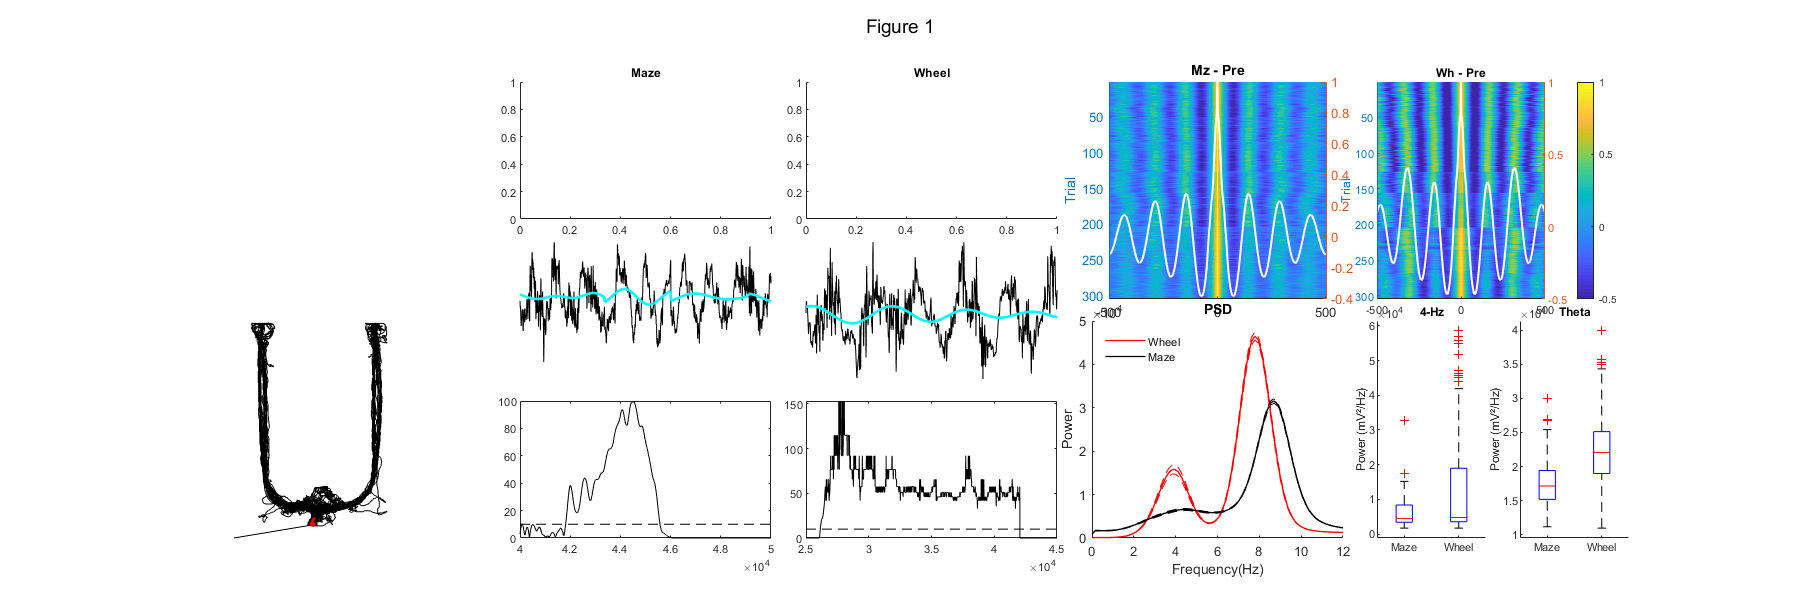

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel A
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
fig = figure(1);clf
fig.Position = [0,0, 1800, 600];
sgtitle('Figure 1')

% a1
subplot(6,10,[1,2,11,12,21,22])
% Space saver
set(gca, 'Visible', 'off')

% a2
subplot(6,10,[31,32,41,42,51,52])
% Load file with coordinates
if ~exist('tempXY')
   tic
   tempXY = load('D:\Ivan\Downloads\ProjetoWheelMaze\Dataset\dryad\Wang_et_al_eLife2016_data_part1~\A498-20120815-01_BehavElectrDataLFP.mat');
   toc
end

% Get coord.
lap    = tempXY.Laps.NLapCW + tempXY.Laps.NLapCCW;
xcoord = tempXY.Track.xMM;
ycoord = tempXY.Track.yMM;
% Plot movimentation ( all )
plot(ycoord(20000:end),xcoord(20000:end),'k-')

% Select one lap ( lap == n )
tempX = [];
tempY = [];
for l=1:max(tempXY.Laps.lapID)
   lapidx = lap == 1;
   tempX = [tempX; xcoord(lapidx)];
   tempY = [tempY; ycoord(lapidx)];
end

hold on
plot(tempY,tempX,'r-')
xlim([0 1600])
ylim([0 1600])
hold off
title('Movement')
set(gca, ...
        'Box',      'off',...
        'Visible', 'off')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel B
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tempData = dataFull{1,1};
% b1.1 Imagesc
subplot(6,10,[3,4,13,14])
title('Maze')

% b1.2 LFP
subplot(6,10,[23,24,33,34])
mzSpeed = tempData.Speed.Mz{1} > 100;
plot(tempData.Lfp{1}(mzSpeed), 'k')
xlim([2000,3500])
hold on
plot(tempData.Delta.Band{1}(mzSpeed), 'c', 'LineWidth', 2)
title('4-Hz Mz')
hold off
set(gca, ...
        'Box',      'off',...
        'Visible', 'off')

% b1.3 Speed
subplot(6,10,[43,44,53,54])
plot(tempData.Speed.Mz{1}/10, 'k')
hold on
plot([0, 5e4], [10, 10],'k--')
xlim([4e4,5e4])

% b2.1 Imagesc
subplot(6,10,[5,6,15,16])
title('Wheel')

% b2.2 LFP
subplot(6,10,[25,26,35,36])
whSpeed = tempData.Speed.Wh{1} > 100;
plot(tempData.Lfp{1}(whSpeed), 'k')
xlim([3000,4000])
hold on
plot(tempData.Delta.Band{1}(whSpeed), 'c', 'LineWidth', 2)
hold off
title('4-Hz Wh')
set(gca, ...
        'Box',      'off',...
        'Visible', 'off')
    
% b2.3 Speed
subplot(6,10,[45,46,55,56])
plot(tempData.Speed.Wh{1}/10, 'k')
hold on
plot([0, 7e4], [10, 10],'k--')
xlim([2.5e4,4.5e4])
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel C
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Pre = 1, Post = 2
nData = 1;

auxMzAcgCombine = [];
auxWhAcgCombine = [];
for i=1:numSubReads
    dataTemp = dataFull{nData, i};
    
    laps = size(dataTemp.Choice, 1);
    for lp=1:laps

        mzMask = dataTemp.Speed.Mz{lp} > 100;
        whMask = dataTemp.Speed.Wh{lp} > 100;

        LFPMz = dataTemp.Lfp{lp}(mzMask);
        LFPWh = dataTemp.Lfp{lp}(whMask);

        % Capture snippet
        [acgMz, lagsMz] = xcorr(LFPMz,'coef', 500);    
        [acgWh, lagsWh] = xcorr(LFPWh,'coef', 500);    

        auxMzAcgCombine = [auxMzAcgCombine, acgMz];
        auxWhAcgCombine = [auxWhAcgCombine, acgWh];
    end
end
% c1
subplot(6,10,[7,8,17,18,27,28])
val = size(auxMzAcgCombine, 1)/2;
xLimValue = -val:val-1;
plotImagesc(lagsMz, auxMzAcgCombine', xLimValue, 'Mz - Pre', [-500,500], 'Trial', 'Lag(ms)', 0, [-0.5, 1], 0, 1)

% c2
subplot(6,10,[9,10,19,20,29,30])
plotImagesc(lagsWh, auxWhAcgCombine', xLimValue, 'Wh - Pre', [-500,500], 'Trial', 'Lag(ms)', 1, [-0.5, 1], 0, 0)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel D
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(6,10,[37,38,47,48,57,58])
nTrials = 0;
data = {struct('Mz', [], 'Wh', []), struct('Mz', [], 'Wh', [])}; 
for i=1:numSubReads
    nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

    dataTemp = dataFull{nData, i}.Pwelch;

    data{nData}.Mz = [data{nData}.Mz; dataTemp.Psd.Mz];
    data{nData}.Wh = [data{nData}.Wh; dataTemp.Psd.Wh];
end

x = dataTemp.Frequency;

plotPSD(x, data{nData}.Wh, data{nData}.Mz, nTrials, nTrials, ["Wheel", "Maze"], 'PSD', ['r', 'k'], 1, [0 , 50000], [0,12], 'Power', 'Frequency(Hz)', 0)
set(gca, 'Box', 'off')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel E
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
lvlZero = struct('Dt', [], 'Th', []);
data = {struct('Mz', lvlZero, 'Wh', lvlZero, 'Freq', []), struct('Mz', lvlZero, 'Wh', lvlZero, 'Freq', [])}; 

nTrials = 0;
for i=1:numSubReads
    dataTemp = dataFull{nData, i}.Pwelch;
    nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);
    
    % 4-Hz
    dtMask = ( dataTemp.Frequency  > 3 ) & ( dataTemp.Frequency  < 5);
    % Theta
    thMask = ( dataTemp.Frequency  > 6 ) & ( dataTemp.Frequency  < 10);

    data{nData}.Mz.Dt = [data{nData}.Mz.Dt; dataTemp.Psd.Mz(:, dtMask)];
    data{nData}.Wh.Dt = [data{nData}.Wh.Dt; dataTemp.Psd.Wh(:, dtMask)];
    data{nData}.Mz.Th = [data{nData}.Mz.Th; dataTemp.Psd.Mz(:, thMask)];
    data{nData}.Wh.Th = [data{nData}.Wh.Th; dataTemp.Psd.Wh(:, thMask)];
end

meanMzDt = mean(data{nData}.Mz.Dt,2);
meanWhDt = mean(data{nData}.Wh.Dt,2);
meanMzTh = mean(data{nData}.Mz.Th,2);
meanWhTh = mean(data{nData}.Wh.Th,2);

% e1
subplot(6,10,[39,49,59])
plotBoxPlot({meanMzDt', meanWhDt'}, ["Maze", "Wheel"], 'Power (mV²/Hz)', [], '4-Hz', []);

% e2
subplot(6,10,[40,50,60])
plotBoxPlot({meanMzTh', meanWhTh'}, ["Maze", "Wheel"], 'Power (mV²/Hz)', [], 'Theta', []);

clearvars -except dataFull srate dt numReads numSubReads tempXY

### **Hippocampal 4-Hz amplitude correlates with running speed**

We next investigated whether hippocampal 4-Hz oscillations are associated with running speed. First, we observed that animals ran faster at the wheel than maze (Figure 2A, red and black, respectively, p < 0.01, Wilcoxon signed-rank test, n = 304 trials), which could suggest that higher running speed underlies the rising of 4-Hz during wheel runs. However, scatter plots show that the instantaneous running speed and the 4-Hz amplitude correlated positively at the wheel and negatively at the maze (Figure 2B, left, r = 0.38 and r = -0.14, respectively, Spearman’s correlation test), indicating that the emergence of 4-Hz oscillations on the wheel can not be only explained by running speed but correlated specifically with running speed on the wheel. In turn, the amplitude of theta oscillations positively correlated with running speed during maze and wheel runs (Figure 2B, right, r = 0.14, and r = 0.01, respectively, Spearman’s correlation test). The instantaneous 4-Hz peak frequency exhibited a positive relationship with running speed during both wheel and maze runs (Figure 2C, left, r = 0.34, and r = 0.27, respectively, Spearman’s correlation test). Similarly, theta peak frequency and running speed were positively correlated at the maze and at the wheel (Figure 2C, right, r = 0.43, and r = 0.24, respectively, Spearman’s correlation test). 

We then evaluated 4-Hz and theta oscillations during wheel runs according to choice performance at the spatial alternation memory task. Figure 2D shows the power spectra at 0-12 Hz obtained from wheel runs previous to correct and incorrect choices. We found that neither 4-Hz nor theta band power was statistically different during wheel runs previous to correct and incorrect choices (Figure 2E, p = 0.257 and p = 0.338, respectively, Wilcoxon rank-sum test). Similarly, neither the 4-Hz nor theta peak frequency was significantly different during wheel runs before correct and incorrect trials (Figure 2F, p = 0.754 and p = 0.36, respectively, Wilcoxon rank-sum test). 

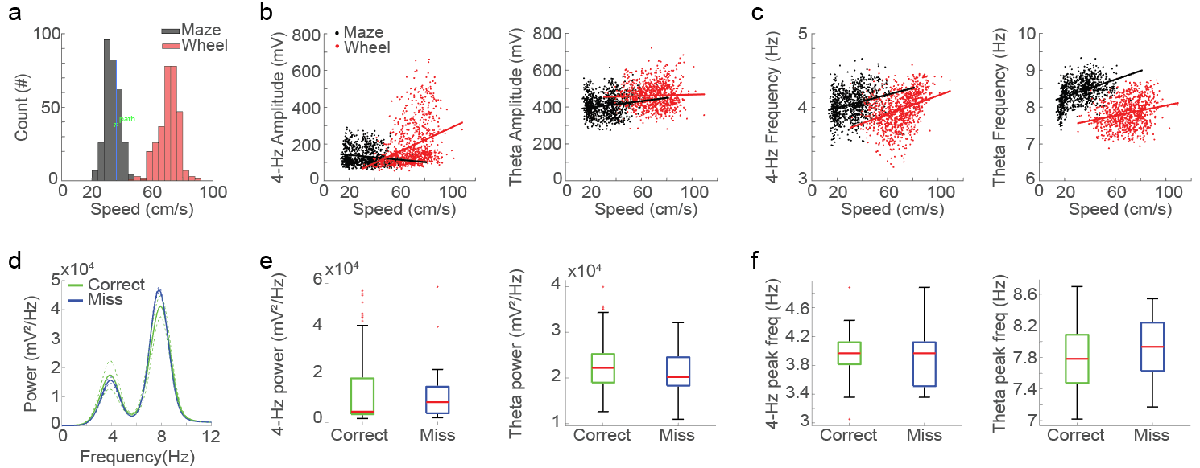

**Figure 2 - Hippocampal 4-Hz oscillations are modulated by running speed but are not affected by memory performance**. **(A)** Histograms of running speeds at the maze (black) and at the wheel (red). **(B)** Scatter plots of running speed and the instantaneous 4-Hz amplitude (left) and theta amplitude (right). **(C)** Scatter plots show the relationship between running speed and the instantaneous 4-Hz frequency (left) and theta frequency (right). **(D)** Average power spectra during wheel run previous to correct (green, n=286 trials) and incorrect (blue, n=18 trials) choices at the spatial alternation memory task. Solid lines represent means and dashed lines represent ± SEM. **(E)** Boxplots of 4-Hz band power (left) and theta band power (right) during wheel runs previous to correct and incorrect choices. **(F)** Boxplots of 4-Hz peak frequency (left) and theta peak frequency (right) during wheel runs before correct and incorrect trials. Supplementary figure XX shows the distribution 4-Hz and theta band power and peak frequency.

% Figura 2
speedthresh=100;
oneStep = struct("Mz", [], "Wh", []);
secStep = struct('Trial', oneStep, 'Full', oneStep);

nData = 1;
respDt = struct('Amp', secStep, 'Fre', secStep);
respTh = struct('Amp', secStep, 'Fre', secStep);
speed = secStep;

for file=1:numSubReads
    dataTemp = dataFull{nData, file};
    
    for session=1:length(dataTemp.Choice)
        % Speed
        speedMzMask = dataTemp.Speed.Mz{session} > speedthresh;
        speedWhMask = dataTemp.Speed.Wh{session} > speedthresh;
        
        speed.Trial.Mz = [ speed.Trial.Mz, mean(dataTemp.Speed.Mz{session}(speedMzMask)) ];
        speed.Trial.Wh = [ speed.Trial.Wh, mean(dataTemp.Speed.Wh{session}(speedWhMask)) ];
        speed.Full.Mz = [ speed.Full.Mz; dataTemp.Speed.Mz{session}(speedMzMask) ];
        speed.Full.Wh = [ speed.Full.Wh; dataTemp.Speed.Wh{session}(speedWhMask) ];
        % Amplitude
        respDt.Amp.Trial.Mz = [respDt.Amp.Trial.Mz, mean(dataTemp.Delta.Amplitude{session}(speedMzMask)) ];
        respDt.Amp.Trial.Wh = [respDt.Amp.Trial.Wh, mean(dataTemp.Delta.Amplitude{session}(speedWhMask)) ];
        respTh.Amp.Trial.Mz = [respTh.Amp.Trial.Mz, mean(dataTemp.Theta.Amplitude{session}(speedMzMask)) ];
        respTh.Amp.Trial.Wh = [respTh.Amp.Trial.Wh, mean(dataTemp.Theta.Amplitude{session}(speedWhMask)) ];
        respDt.Amp.Full.Mz = [respDt.Amp.Full.Mz; dataTemp.Delta.Amplitude{session}(speedMzMask)' ];
        respDt.Amp.Full.Wh = [respDt.Amp.Full.Wh; dataTemp.Delta.Amplitude{session}(speedWhMask)' ];
        respTh.Amp.Full.Mz = [respTh.Amp.Full.Mz; dataTemp.Theta.Amplitude{session}(speedMzMask)' ];
        respTh.Amp.Full.Wh = [respTh.Amp.Full.Wh; dataTemp.Theta.Amplitude{session}(speedWhMask)' ];
        % Frequency
        respDt.Fre.Trial.Mz = [respDt.Fre.Trial.Mz, mean(dataTemp.Delta.InstFreq{session}(speedMzMask)) ];
        respDt.Fre.Trial.Wh = [respDt.Fre.Trial.Wh, mean(dataTemp.Delta.InstFreq{session}(speedWhMask)) ];
        respTh.Fre.Trial.Mz = [respTh.Fre.Trial.Mz, mean(dataTemp.Theta.InstFreq{session}(speedMzMask)) ];
        respTh.Fre.Trial.Wh = [respTh.Fre.Trial.Wh, mean(dataTemp.Theta.InstFreq{session}(speedWhMask)) ];
        respDt.Fre.Full.Mz = [respDt.Fre.Full.Mz; dataTemp.Delta.InstFreq{session}(speedMzMask)' ];
        respDt.Fre.Full.Wh = [respDt.Fre.Full.Wh; dataTemp.Delta.InstFreq{session}(speedWhMask)' ];
        respTh.Fre.Full.Mz = [respTh.Fre.Full.Mz; dataTemp.Theta.InstFreq{session}(speedMzMask)' ];
        respTh.Fre.Full.Wh = [respTh.Fre.Full.Wh; dataTemp.Theta.InstFreq{session}(speedWhMask)' ];
        
    end
end

secondStep = struct('Dt', oneStep, 'Th', oneStep);
binsResp = struct('Speed', secondStep, 'Amp', secondStep,'Fre', secondStep);
% thirdStep = struct('R_Amp', oneStep, 'P_Amp', oneStep, 'R_Fre', oneStep, 'P_Fre', oneStep);
% rpBin = struct('Dt', thirdStep, 'Th', thirdStep);

t=5; %bin in sec
count=1;
for i=1:(t*srate):length(speed.Full.Mz)-(t*srate)
    try
        binsResp.Speed.Dt.Mz = [binsResp.Speed.Dt.Mz, mean(speed.Full.Mz(count:count+(t*srate))) ];
        binsResp.Amp.Dt.Mz = [binsResp.Amp.Dt.Mz, mean(respDt.Amp.Full.Mz(count:count+(t*srate))) ];
        binsResp.Fre.Dt.Mz = [binsResp.Fre.Dt.Mz, mean(respDt.Fre.Full.Mz(count:count+(t*srate))) ];

        binsResp.Speed.Th.Mz = [binsResp.Speed.Th.Mz, mean(speed.Full.Mz(count:count+(t*srate))) ];
        binsResp.Amp.Th.Mz = [binsResp.Amp.Th.Mz, mean(respTh.Amp.Full.Mz(count:count+(t*srate))) ];
        binsResp.Fre.Th.Mz = [binsResp.Fre.Th.Mz, mean(respTh.Fre.Full.Mz(count:count+(t*srate))) ];
        count=count+(t*srate);
    end
end

count=1;
for i=1:(t*srate):length(speed.Full.Wh)-(t*srate)
    try
        binsResp.Speed.Dt.Wh = [binsResp.Speed.Dt.Wh, mean(speed.Full.Wh(count:count+(t*srate))) ];
        binsResp.Amp.Dt.Wh = [binsResp.Amp.Dt.Wh, mean(respDt.Amp.Full.Wh(count:count+(t*srate))) ];
        binsResp.Fre.Dt.Wh = [binsResp.Fre.Dt.Wh, mean(respDt.Fre.Full.Wh(count:count+(t*srate))) ];

        binsResp.Speed.Th.Wh = [binsResp.Speed.Th.Wh, mean(speed.Full.Wh(count:count+(t*srate))) ];
        binsResp.Amp.Th.Wh = [binsResp.Amp.Th.Wh, mean(respTh.Amp.Full.Wh(count:count+(t*srate))) ];
        binsResp.Fre.Th.Wh = [binsResp.Fre.Th.Wh, mean(respTh.Fre.Full.Wh(count:count+(t*srate))) ];
        count=count+(t*srate);
    end
end
clearvars -except dataFull srate dt numReads numSubReads tempXY respDt respTh speed binsResp nData

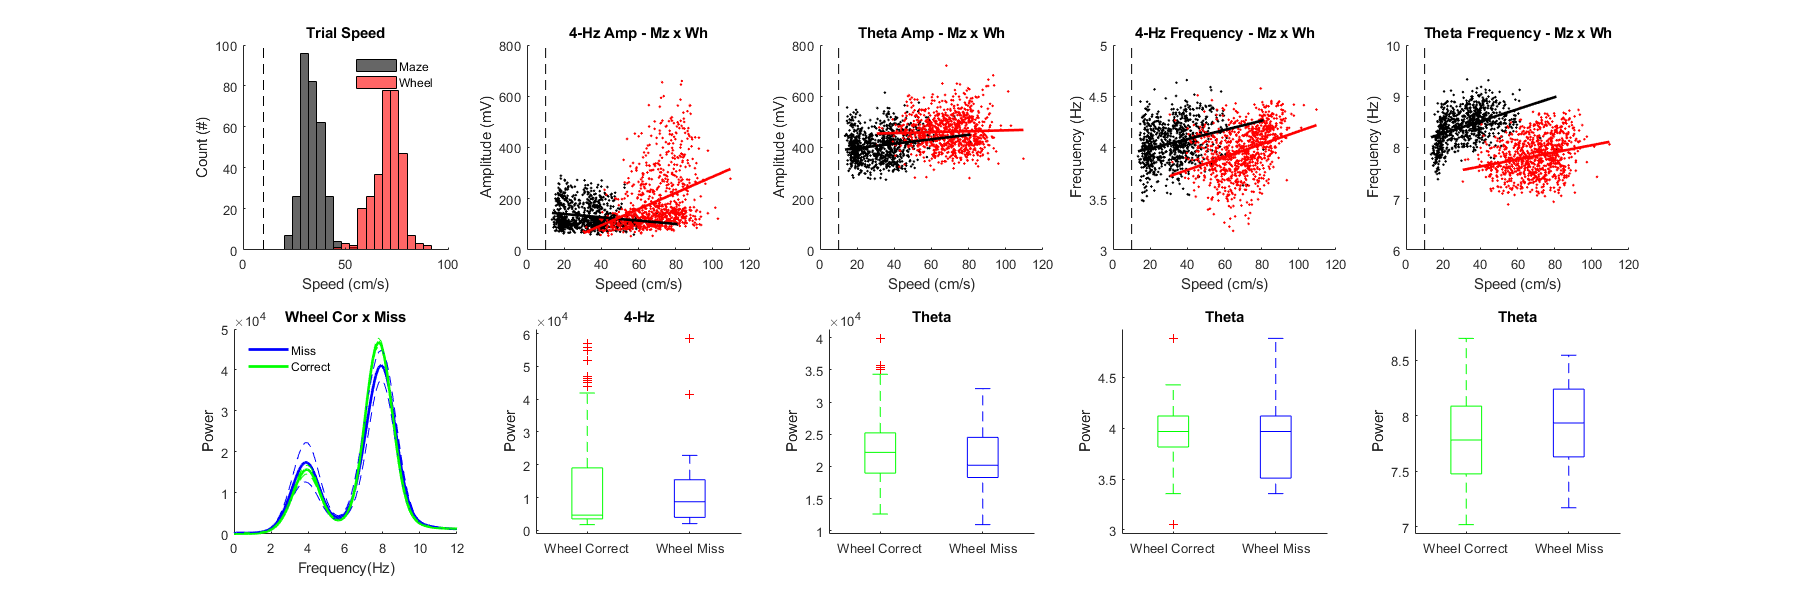

speedthresh = 10;
fig = figure(2);clf
fig.Position = [0,0, 1800, 600];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel A
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(2,5,1)
bins=[0:4:100];
histogram(speed.Trial.Mz/10,bins,'FaceColor',[0 0 0])
hold on
histogram(speed.Trial.Wh/10,bins,'FaceColor',[1 0 0])
plot([speedthresh, speedthresh],[0 100],'k--')
xlim([0, 100])
xlabel 'Speed (cm/s)'
ylabel 'Count (#)'
title('Trial Speed')
label1{1} = 'Maze';
label1{2} = 'Wheel';
box off
legend(label1,'location','northeast')
legend('boxoff')
axis square
hold off
set(gca, 'Box', 'off')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel B
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% b1
subplot(2,5,2)
plotScatterNCorr(binsResp.Speed.Dt.Mz/10, binsResp.Amp.Dt.Mz, binsResp.Speed.Dt.Wh/10, binsResp.Amp.Dt.Wh,  speedthresh, [0, 800], [0, 120],...
        [0], '4-Hz Amp - Mz x Wh', 'Speed (cm/s)', 'Amplitude (mV)', 1.5)
set(gca, 'Box', 'off')
% b2
subplot(2,5,3)
% Speed x Power corr Theta
plotScatterNCorr(binsResp.Speed.Th.Mz/10, binsResp.Amp.Th.Mz, binsResp.Speed.Th.Wh/10, binsResp.Amp.Th.Wh,  speedthresh, [0, 800], [0, 120],...
    [0], 'Theta Amp - Mz x Wh', 'Speed (cm/s)', 'Amplitude (mV)', 1.5)
set(gca, 'Box', 'off')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel C
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% c1
subplot(2,5,4)
% Speed x Fre corr
plotScatterNCorr(binsResp.Speed.Dt.Mz/10, binsResp.Fre.Dt.Mz, binsResp.Speed.Dt.Wh/10, binsResp.Fre.Dt.Wh,  speedthresh, [0, 5], [0, 120],...
    [3, 5],  '4-Hz Frequency - Mz x Wh', 'Speed (cm/s)', 'Frequency (Hz)', 1.5)
set(gca, 'Box', 'off')
% c2
subplot(2,5,5)
% Speed x Fre corr
plotScatterNCorr(binsResp.Speed.Th.Mz/10, binsResp.Fre.Th.Mz, binsResp.Speed.Th.Wh/10, binsResp.Fre.Th.Wh,  speedthresh, [6, 10], [0, 120],...
    [6, 10],  'Theta Frequency - Mz x Wh', 'Speed (cm/s)', 'Frequency (Hz)', 1.5)
set(gca, 'Box', 'off')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel D
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(2,5,6)
data = {struct('Mz', [], 'Wh', [], 'nTrials' , 0), struct('Mz', [], 'Wh', [], 'nTrials' , 0)}; 

for chc=1:2
    for i=1:numSubReads
        data{chc}.nTrials = data{chc}.nTrials + sum(dataFull{nData, i}.Choice == chc-1);
        
        dataTemp = dataFull{nData, i}.Pwelch;
        cMask = dataTemp.Choice == chc-1;

        data{chc}.Wh = [data{chc}.Wh; dataTemp.Psd.Wh(cMask, :)];
        data{chc}.Mz = [data{chc}.Mz; dataTemp.Psd.Mz(cMask, :)];
    end

end

x = dataTemp.Frequency;

plotPSD(x, data{1}.Wh, data{2}.Wh, data{1}.nTrials, data{2}.nTrials, ["Miss", "Correct"], 'Wheel Cor x Miss', ['b', 'g'], 2, [0, 50000], [0, 12], 'Power', 'Frequency(Hz)', 0);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel E
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

lvlZero = struct('Dt', [], 'Th', []);
data = {struct('MzC', lvlZero, 'WhC', lvlZero, 'MzE', lvlZero, 'WhE', lvlZero, 'Freq', []), ...
    struct('MzC', lvlZero, 'WhC', lvlZero, 'MzE', lvlZero, 'WhE', lvlZero, 'Freq', [])}; 

nTrials = 0;
for i=1:numSubReads
    dataTemp = dataFull{nData, i}.Pwelch;
    nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

    % 4-Hz
    dtMask = ( dataTemp.Frequency  > 3 ) & ( dataTemp.Frequency  < 5);
    % Theta
    thMask = ( dataTemp.Frequency  > 6 ) & ( dataTemp.Frequency  < 10);
    cMask = dataTemp.Choice == 0;

    data{nData}.MzC.Dt = [data{nData}.MzC.Dt; dataTemp.Psd.Mz(~cMask, dtMask)];
    data{nData}.WhC.Dt = [data{nData}.WhC.Dt; dataTemp.Psd.Wh(~cMask, dtMask)];
    data{nData}.MzC.Th = [data{nData}.MzC.Th; dataTemp.Psd.Mz(~cMask, thMask)];
    data{nData}.WhC.Th = [data{nData}.WhC.Th; dataTemp.Psd.Wh(~cMask, thMask)];
    
    data{nData}.MzE.Dt = [data{nData}.MzE.Dt; dataTemp.Psd.Mz(cMask, dtMask)];
    data{nData}.WhE.Dt = [data{nData}.WhE.Dt; dataTemp.Psd.Wh(cMask, dtMask)];
    data{nData}.MzE.Th = [data{nData}.MzE.Th; dataTemp.Psd.Mz(cMask, thMask)];
    data{nData}.WhE.Th = [data{nData}.WhE.Th; dataTemp.Psd.Wh(cMask, thMask)];

end

% e1
subplot(2,5,7)

x = mean(data{nData}.Freq, 2);
meanWhC = mean(data{nData}.WhC.Dt,2);
meanMzC = mean(data{nData}.MzC.Dt,2);
meanWhE = mean(data{nData}.WhE.Dt,2);
meanMzE = mean(data{nData}.MzE.Dt,2);

plotBoxPlot({meanWhC', meanWhE'}, ["Wheel Correct", "Wheel Miss"], "Power", [], "4-Hz", ['g','b'])
axis square

% e2
subplot(2,5,8)
x = mean(data{nData}.Freq, 2);
meanWhC = mean(data{nData}.WhC.Th,2);
meanMzC = mean(data{nData}.MzC.Th,2);
meanWhE = mean(data{nData}.WhE.Th,2);
meanMzE = mean(data{nData}.MzE.Th,2);

plotBoxPlot({meanWhC', meanWhE'}, ["Wheel Correct", "Wheel Miss"], "Power", [], "Theta", ['g','b'])
axis square

% Panel F
% f1
subplot(2,5,9)
peakWhC = getPeakVal(data{nData}.WhC.Dt', dataTemp.Frequency(dtMask));
peakWhE = getPeakVal(data{nData}.WhE.Dt', dataTemp.Frequency(dtMask));

plotBoxPlot({peakWhC, peakWhE}, ["Wheel Correct", "Wheel Miss"], "Power", [], "Theta", ['g','b'])
axis square

% f2
subplot(2,5,10)
peakWhC = getPeakVal(data{nData}.WhC.Th', dataTemp.Frequency(thMask));
peakWhE = getPeakVal(data{nData}.WhE.Th', dataTemp.Frequency(thMask));

plotBoxPlot({peakWhC, peakWhE}, ["Wheel Correct", "Wheel Miss"], "Power", [], "Theta", ['g','b'])
axis square


clearvars -except dataFull srate dt numReads numSubReads tempXY respDt respTh speed binsResp nData

### **Hippocampal 4-Hz oscillations are resistant to medial septum inactivation **

Next, we evaluated how the inactivation of the medial septum through muscimol microinjections, a GABA receptor agonist, affects 4-Hz and theta oscillations during wheel runs. Muscimol injection significantly reduced running speed on the wheel (Figure 3A, p < 0.01, Wilcoxon rank-sum test, n = 304 and 501 trials before and after injections, respectively). It also disrupted choice performance at the spatial alternation memory task (Pre: 94.45% and Post: 59.61% correct choices; Supplementary Figure XX, p < 0.01, Wilcoxon rank-sum test). Autocorrelograms of hippocampal LFP show that muscimol injection in the medial septum affected hippocampal theta rhythmicity while surprisingly preserved 4-Hz oscillations unchanged (Figure 3B). Average power spectra revealed that medial septum inactivation abolished theta, but not 4-Hz oscillations (Figure 3C). Muscimol injections did not change the distribution of 4-Hz power (Figure 3D, left, p = 0.86, Wilcoxon rank-sum test), and significantly decreased the distribution of theta power (Figure 3D, right, p < 0.01, Wilcoxon rank-sum test). In addition, muscimol injections significantly reduced both the 4-Hz and theta band peak frequency (Figure 3E,  left and right, p = XXX and p = XXX, respectively, Wilcoxon rank-sum test). 

We next evaluated whether the effects of medial septum inactivation on 4-Hz and theta amplitude and frequency were dependent on running speed on the wheel (Figure 3F, left and right, respectively). As shown in Figure 3G, the instantaneous 4-Hz amplitude increased with animal speed; moreover, such increase was similar before and after muscimol injection (left, r = XX and r = XX; Pearson’s correlation). In contrast, the instantaneous theta amplitude significantly reduced after muscimol injection even at identical running speeds (Figure 3E, right, r = XX and r = XX; Pearson’s correlation). Additionaly, muscimol injections did not affect neither the instantaneous 4-Hz nor theta peak frequency ().

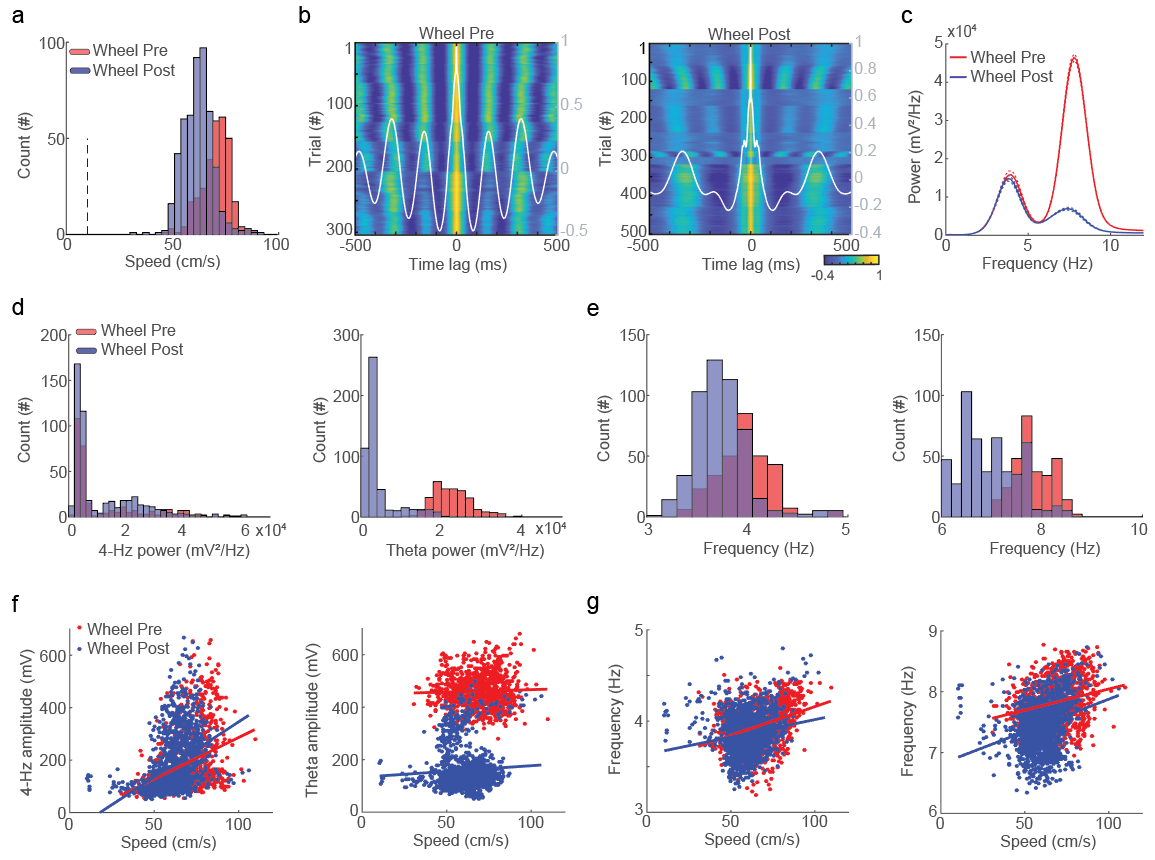

**Figure 3 - Hippocampal 4-Hz oscillations are resistant to pharmacological inactivation of the medial septum. (A) **Histograms of running speed at the wheel before (red, n=304 trials) and after (blue, n=501 trials) muscimol inactivation of the medial septum. **(B) **Color-coded autocorrelograms of LFP signals across runs at the wheel before (left) and after (right) muscimol. Gray traces represent the average autocorrelograms.** (C) **Average power spectra at 0-12 Hz during wheel runs. Solid lines represent the mean and dashed lines represent ± SEM. **(D)** Histograms of 4-Hz band power (left) and theta band power (right) before and after muscimol. **(E)** Histograms of 4-Hz band peak frequency (left) and theta band peak frequency (right) before and after muscimol.** (F) **Scatter plots of running speed and the instantaneous amplitude of 4-Hz (left) and theta (right) oscillations before and after muscimol. **(G) **Scatter plots of running speed and the instantaneous frequency of 4-Hz (left) and theta (right) oscillations before and after muscimol.

%% Save/Load Data
if ~exist('dataUnorm')
    tic
    savePath = 'H:\.shortcut-targets-by-id\1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_\ProjetoWheelMaze\Dataset\DRYAD\Single Files';
    file = sprintf('%s/%s.mat', savePath, 'AcgPwelchData');
    load(file)
    toc
end

Elapsed time is 6.323208 seconds.


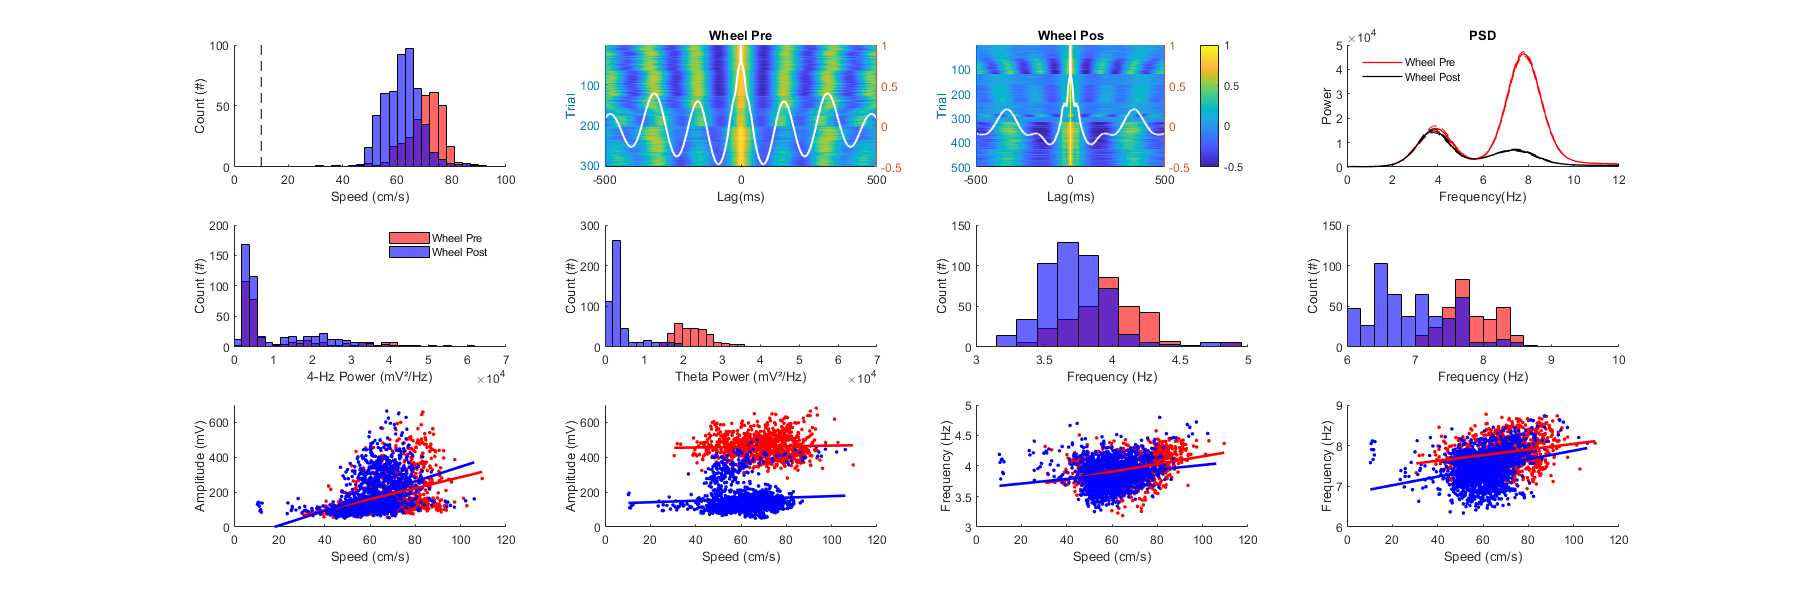

if ~exist('psdPrPo')
    psdPrPo = load('H:\.shortcut-targets-by-id\1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_\ProjetoWheelMaze\Resultados\TrialByTrial\TrialbyTrial_PsdPeak_PrePos.mat');
end
if ~exist('speedPrPo')
    speedPrPo = load('H:\.shortcut-targets-by-id\1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_\ProjetoWheelMaze\Resultados\TrialByTrial\TrialbyTrial_SpdDtThAmpFre_PrePos.mat');
    % Convert mm/sec to cm/sec
    speedPrPo.PRE.SpeedWh = speedPrPo.PRE.SpeedWh/10;
    speedPrPo.POS.SpeedWh = speedPrPo.POS.SpeedWh/10;
    speedPrPo.PRE.binSpdWh = speedPrPo.PRE.binSpdWh/10;
    speedPrPo.POS.binSpdWh = speedPrPo.POS.binSpdWh/10;
end

% fig 3
fig = figure(3);clf
fig.Position = [0,0, 1800, 600];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel A
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%a1
subplot(3,4,1)
bins=[0:3:100];
speedthresh = 10;
histogram(speedPrPo.PRE.SpeedWh,bins,'FaceColor',[1 0 0])
hold on
histogram(speedPrPo.POS.SpeedWh,bins,'FaceColor',[0 0 1])
plot([speedthresh speedthresh],[0, 100],'k--')
xlim([0, 100])
xlabel 'Speed (cm/s)'
ylabel 'Count (#)'
set(gca, 'Box', 'off')
% axis square

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel B
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
auxWhAcgCombine = {[], []};
for nData = 1:2
    for i=1:numSubReads
        dataTemp = dataFull{nData, i};
        
        laps = size(dataTemp.Choice, 1);
        for lp=1:laps
    
            whMask = dataTemp.Speed.Wh{lp} > 100;
    
            LFPWh = dataTemp.Lfp{lp}(whMask);
    
            % Capture snippet 
            [acgWh, lagsWh] = xcorr(LFPWh,'coef', 500);    
    
            auxWhAcgCombine{nData} = [auxWhAcgCombine{nData}, acgWh];
        end
    end
end
% b1
subplot(3,4,2)
val = size(auxWhAcgCombine{1}, 1)/2;
xLimValue = -val:val-1;
plotImagesc(lagsWh, auxWhAcgCombine{1}', xLimValue, 'Wheel Pre', [-500,500], 'Trial', 'Lag(ms)', 0, 0, 0, 0)

% b2
subplot(3,4,3)
plotImagesc(lagsWh, auxWhAcgCombine{2}', xLimValue, 'Wheel Pos', [-500,500], 'Trial', 'Lag(ms)', 1, [-0.5, 1], 0, 0)


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel C
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot(3,4,4) % Conferir
nTrialsF = 0;
nTrialsS = 0;
dataStruct = struct('Pre', [], 'Post', []); 
for i=1:numSubReads
    nTrialsF = nTrialsF + size(dataFull{1, i}.Choice, 1);
    nTrialsS = nTrialsS + size(dataFull{2, i}.Choice, 1);
    
    dataStruct.Pre = [dataStruct.Pre; dataFull{1, i}.Pwelch.Psd.Wh];
    dataStruct.Post = [dataStruct.Post; dataFull{2, i}.Pwelch.Psd.Wh];
end

x = dataTemp.Pwelch.Frequency;

plotPSD(x, dataStruct.Pre, dataStruct.Post, nTrialsF, nTrialsS, ["Wheel Pre", "Wheel Post"], 'PSD', ['r', 'k'], 1, [0 , 5e4], [0,12], 'Power', 'Frequency(Hz)', 0)
set(gca, 'Box', 'off')
% axis square

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel D
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% d1
subplot(3,4,5)
bins=[0:0.2:7]*10^4;
histogram(psdPrPo.PRE.PsdDtWh,bins,'FaceColor',[1 0 0])
hold on
histogram(psdPrPo.POS.PsdDtWh,bins,'FaceColor',[0 0 1])
label1 = 'Wheel Pre';
label2 = 'Wheel Post';
legend({label1, label2}, "Box","off", "Location","best")
xlim([0, 7e4])
xlabel '4-Hz Power (mV²/Hz)'
ylabel 'Count (#)'
set(gca, 'Box', 'off')
% axis square


% d2
subplot(3,4,6)
bins=[0:0.2:5]*10^4;
histogram(psdPrPo.PRE.PsdThWh,bins,'FaceColor',[1 0 0])
hold on
histogram(psdPrPo.POS.PsdThWh,bins,'FaceColor',[0 0 1])
xlim([0, 7e4])
xlabel 'Theta Power (mV²/Hz)'
ylabel 'Count (#)'
set(gca, 'Box', 'off')
% axis square

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel E
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% e1
subplot(3,4,7)
bins=[3:0.15:5];
histogram(psdPrPo.PRE.peakfreqWhDt,bins,'FaceColor',[1 0 0])
hold on
histogram(psdPrPo.POS.peakfreqWhDt,bins,'FaceColor',[0 0 1])
xlim([3 5])
xlabel 'Frequency (Hz)'
ylabel 'Count (#)'
set(gca, 'Box', 'off')
% axis square

% e2
subplot(3,4,8)
bins=[6:0.2:10];
histogram(psdPrPo.PRE.peakfreqWhTh,bins,'FaceColor',[1 0 0])
hold on
histogram(psdPrPo.POS.peakfreqWhTh,bins,'FaceColor',[0 0 1])
xlim([6, 10])
ylim([0, 150])
xlabel 'Frequency (Hz)'
ylabel 'Count (#)'
set(gca, 'Box', 'off')
% axis square

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel F
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% f1
subplot(3,4,9)
plot(speedPrPo.PRE.binSpdWh,speedPrPo.PRE.binDtAmpWh,'or','markerfacecolor','r','markersize',2)
hold on
plot(speedPrPo.POS.binSpdWh,speedPrPo.POS.binDtAmpWh,'ob','markerfacecolor','b','markersize',2)
xlabel 'Speed (cm/s)'
ylabel 'Amplitude (mV)'
xlim([0, 120])
ylim([0, 700])
coefAmpPRE=polyfit(speedPrPo.PRE.binSpdWh,speedPrPo.PRE.binDtAmpWh,1);
plot(speedPrPo.PRE.binSpdWh,polyval(coefAmpPRE,speedPrPo.PRE.binSpdWh),'r-','linewidth',2)
coefAmpPOS=polyfit(speedPrPo.POS.binSpdWh,speedPrPo.POS.binDtAmpWh,1);
plot(speedPrPo.POS.binSpdWh,polyval(coefAmpPOS,speedPrPo.POS.binSpdWh),'b-','linewidth',2)
set(gca, 'Box', 'off')
% axis square

% f2
subplot(3,4,10)
plot(speedPrPo.PRE.binSpdWh,speedPrPo.PRE.binThAmpWh,'or','markerfacecolor','r','markersize',2)
hold on
plot(speedPrPo.POS.binSpdWh,speedPrPo.POS.binThAmpWh,'ob','markerfacecolor','b','markersize',2)
xlabel 'Speed (cm/s)'
ylabel 'Amplitude (mV)'
xlim([0, 120])
ylim([0, 700])
coefAmpPRE=polyfit(speedPrPo.PRE.binSpdWh,speedPrPo.PRE.binThAmpWh,1);
plot(speedPrPo.PRE.binSpdWh,polyval(coefAmpPRE,speedPrPo.PRE.binSpdWh),'r-','linewidth',2)
coefAmpPOS=polyfit(speedPrPo.POS.binSpdWh,speedPrPo.POS.binThAmpWh,1);
plot(speedPrPo.POS.binSpdWh,polyval(coefAmpPOS,speedPrPo.POS.binSpdWh),'b-','linewidth',2)
set(gca, 'Box', 'off')
% axis square

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel G
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% g1
subplot(3,4,11)
plot(speedPrPo.PRE.binSpdWh,speedPrPo.PRE.binDtFreWh,'or','markerfacecolor','r','markersize',2)
hold on
plot(speedPrPo.POS.binSpdWh,speedPrPo.POS.binDtFreWh,'ob','markerfacecolor','b','markersize',2)
xlabel 'Speed (cm/s)'
ylabel 'Frequency (Hz)'
xlim([0, 120])
ylim([3, 5])
coefFrePRE=polyfit(speedPrPo.PRE.binSpdWh,speedPrPo.PRE.binDtFreWh,1);
plot(speedPrPo.PRE.binSpdWh,polyval(coefFrePRE,speedPrPo.PRE.binSpdWh),'r-','linewidth',2)
coefFrePOS=polyfit(speedPrPo.POS.binSpdWh,speedPrPo.POS.binDtFreWh,1);
plot(speedPrPo.POS.binSpdWh,polyval(coefFrePOS,speedPrPo.POS.binSpdWh),'b-','linewidth',2) 
set(gca, 'Box', 'off')
% axis square

% g2
subplot(3,4,12)
plot(speedPrPo.PRE.binSpdWh,speedPrPo.PRE.binThFreWh,'or','markerfacecolor','r','markersize',2)
hold on
plot(speedPrPo.POS.binSpdWh,speedPrPo.POS.binThFreWh,'ob','markerfacecolor','b','markersize',2)
xlabel 'Speed (cm/s)'
ylabel 'Frequency (Hz)'
xlim([0, 120])
ylim([6, 9])
coefFrePRE=polyfit(speedPrPo.PRE.binSpdWh,speedPrPo.PRE.binThFreWh,1);
plot(speedPrPo.PRE.binSpdWh,polyval(coefFrePRE,speedPrPo.PRE.binSpdWh),'r-','linewidth',2)
coefFrePOS=polyfit(speedPrPo.POS.binSpdWh,speedPrPo.POS.binThFreWh,1); 
plot(speedPrPo.POS.binSpdWh,polyval(coefFrePOS,speedPrPo.POS.binSpdWh),'b-','linewidth',2)
set(gca, 'Box', 'off')

% axis square
clearvars -except dataFull srate dt numReads numSubReads nData data dataUnorm speedPrPo psdPrPo

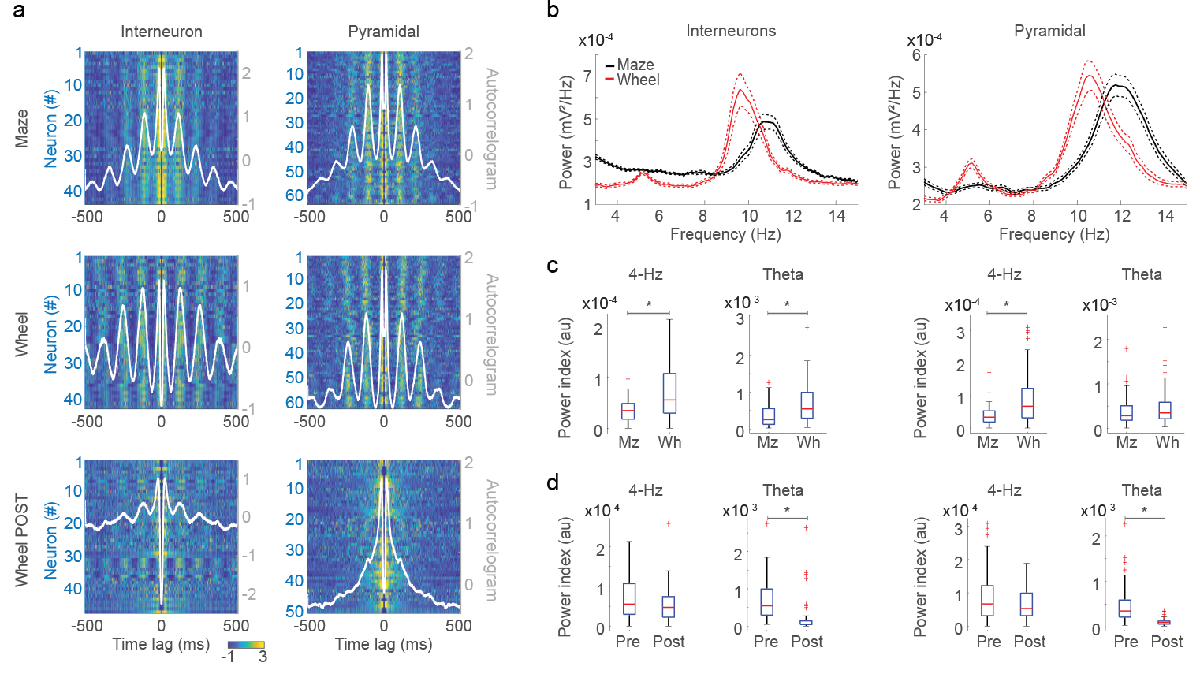

**Figure 4 - Spiking activity exhibits 4-Hz oscillations. **Maze versus wheel running: Interneurons at 4 Hz p < 0.01; Interneurons at theta p < 0.01; Pyramidal at 4 Hz p <= 0.01; Pyramidal at theta p = 0.20708; Pre versus post-muscimol during wheel running: Interneurons at 4 Hz p = 0.13903; Interneurons at theta p <= 0.01; Pyramidal at 4 Hz p = 0.24289; Pyramidal at theta p <= 0.01; 

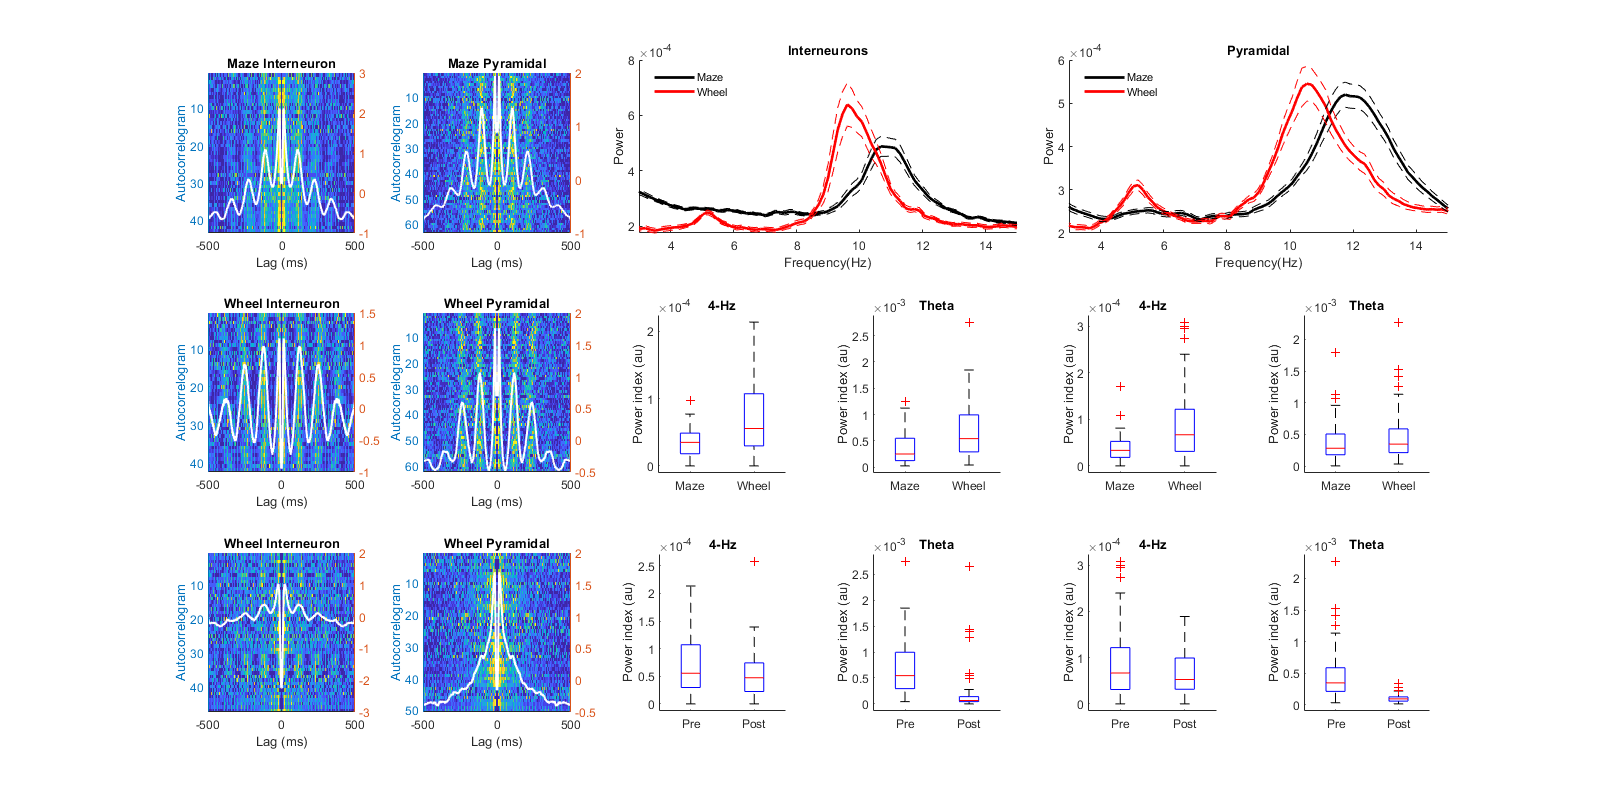

%% Save/Load Data
if ~exist('dataUnorm')
    tic
    savePath = 'H:\.shortcut-targets-by-id\1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_\ProjetoWheelMaze\Dataset\DRYAD\Single Files';
    file = sprintf('%s/%s.mat', savePath, 'AcgPwelchData');
    load(file)
    toc
end
% Fig 4
fig = figure(4);clf
fig.Position = [0,0, 1600, 800];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel A
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
PREPOS=1;
value=0.2;
sm=20;

% a1
subplot(3,6,1)

% axis values
yVal = data{PREPOS}.Mz.Acg.Int;
xHalf = floor(size(yVal,2)/2);
xVal = -xHalf:10:xHalf;
lim = find(mean(yVal,2)>value);
combine = zscore(yVal(lim,:),[],2);

plotImagesc(xVal, combine, dataUnorm{PREPOS}.AcgLags, 'Maze Interneuron', 0, 'Autocorrelogram', 'Lag (ms)', 0, [-1,3], sm, 0)
% a2
subplot(3,6,2)
yVal = data{PREPOS}.Mz.Acg.Pyr;
xHalf = floor(size(yVal,2)/2);
xVal = -xHalf:10:xHalf;
lim = find(mean(yVal,2)>value);
combine = zscore(yVal(lim,:),[],2);

plotImagesc(xVal, combine, dataUnorm{PREPOS}.AcgLags, 'Maze Pyramidal', 0, 'Autocorrelogram', 'Lag (ms)', 0, [-1,3], sm, 0)
% a3
subplot(3,6,7)
yVal = data{PREPOS}.Wh.Acg.Int;
xHalf = floor(size(yVal,2)/2);
xVal = -xHalf:10:xHalf;
lim = find(mean(yVal,2)>value);
combine = zscore(yVal(lim,:),[],2);

plotImagesc(xVal, combine, dataUnorm{PREPOS}.AcgLags, 'Wheel Interneuron', 0, 'Autocorrelogram', 'Lag (ms)', 0, [-1,3], sm, 0)
% a4
subplot(3,6,8)
yVal = data{PREPOS}.Wh.Acg.Pyr;
xHalf = floor(size(yVal,2)/2);
xVal = -xHalf:10:xHalf;
lim = find(mean(yVal,2)>value);
combine = zscore(yVal(lim,:),[],2);

plotImagesc(xVal, combine, dataUnorm{PREPOS}.AcgLags, 'Wheel Pyramidal', 0, 'Autocorrelogram', 'Lag (ms)', 0, [-1,3], sm, 0)
% a5
PREPOS = 2;
subplot(3,6,13)
yVal = data{PREPOS}.Wh.Acg.Int;
xHalf = floor(size(yVal,2)/2);
xVal = -xHalf:10:xHalf;
lim = find(mean(yVal,2)>value);
combine = zscore(yVal(lim,:),[],2);

plotImagesc(xVal, combine, dataUnorm{PREPOS}.AcgLags, 'Wheel Interneuron', 0, 'Autocorrelogram', 'Lag (ms)', 0, [-1,3], sm, 0)
% a6
subplot(3,6,14)
yVal = data{PREPOS}.Wh.Acg.Pyr;
xHalf = floor(size(yVal,2)/2);
xVal = -xHalf:10:xHalf;
lim = find(mean(yVal,2)>value);
combine = zscore(yVal(lim,:),[],2);

plotImagesc(xVal, combine, dataUnorm{PREPOS}.AcgLags, 'Wheel Pyramidal', 0, 'Autocorrelogram', 'Lag (ms)', 0, [-1,3], sm, 0)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel B
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
PREPOS = 1;
value = 0.2;
% b1
subplot(3,6,[3, 4])
limMzInt=find(mean(data{PREPOS}.Mz.Acg.Int,2)>value);
limWhInt=find(mean(data{PREPOS}.Wh.Acg.Int,2)>value);
plotPSD(dataUnorm{PREPOS}.PwelchF, data{PREPOS}.Mz.Pwelch.Int(limMzInt,:), data{PREPOS}.Wh.Pwelch.Int(limWhInt,:), size(data{PREPOS}.Mz.Pwelch.Int(limMzInt,:),1),...
    size(data{PREPOS}.Wh.Pwelch.Int(limWhInt,:),1), ["Maze", "Wheel"], 'Interneurons', ['k', 'r'], 2, 0, [3, 15], 'Power', 'Frequency(Hz)', 0)

% b2
subplot(3,6,[5, 6])
limMzPyr=find(mean(data{PREPOS}.Mz.Acg.Pyr,2)>value);
limWhPyr=find(mean(data{PREPOS}.Wh.Acg.Pyr,2)>value);
plotPSD(dataUnorm{PREPOS}.PwelchF, data{PREPOS}.Mz.Pwelch.Pyr(limMzPyr,:), data{PREPOS}.Wh.Pwelch.Pyr(limWhPyr,:), size(data{PREPOS}.Mz.Pwelch.Pyr(limMzPyr,:),1),...
    size(data{PREPOS}.Wh.Pwelch.Pyr(limWhPyr,:),1), ["Maze", "Wheel"], 'Pyramidal', ['k', 'r'], 2, 0, [3, 15], 'Power', 'Frequency(Hz)', 0)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel C
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Dt=find(dataUnorm{PREPOS}.PwelchF>4 & dataUnorm{PREPOS}.PwelchF<6); % 3 - 5
Th=find(dataUnorm{PREPOS}.PwelchF>8 & dataUnorm{PREPOS}.PwelchF<15); % 6 - 10

% c1
subplot(3,6,9)
yMz = max(data{PREPOS}.Mz.Pwelch.Int(limMzInt,Dt),[],2) - data{PREPOS}.Mz.Pwelch.Int(limMzInt,Dt(end));
yWh = max(data{PREPOS}.Wh.Pwelch.Int(limWhInt,Dt),[],2) - data{PREPOS}.Wh.Pwelch.Int(limWhInt,Dt(end));

plotBoxPlot({yMz', yWh'}, ["Maze", "Wheel"], "Power index (au)", [], "4-Hz", [])

% c2
subplot(3,6,10)
yMz = max(data{PREPOS}.Mz.Pwelch.Int(limMzInt,Th),[],2) - data{PREPOS}.Mz.Pwelch.Int(limMzInt,Th(end));
yWh = max(data{PREPOS}.Wh.Pwelch.Int(limWhInt,Th),[],2) - data{PREPOS}.Wh.Pwelch.Int(limWhInt,Th(end));

plotBoxPlot({yMz', yWh'}, ["Maze", "Wheel"], "Power index (au)", [], "Theta", [])

% c3
subplot(3,6,11)
yMz = max(data{PREPOS}.Mz.Pwelch.Pyr(limMzPyr,Dt),[],2) - data{PREPOS}.Mz.Pwelch.Pyr(limMzPyr,Dt(end));
yWh = max(data{PREPOS}.Wh.Pwelch.Pyr(limWhPyr,Dt),[],2) - data{PREPOS}.Wh.Pwelch.Pyr(limWhPyr,Dt(end));

plotBoxPlot({yMz', yWh'}, ["Maze", "Wheel"], "Power index (au)", [], "4-Hz", [])

% c4
subplot(3,6,12)
yMz = max(data{PREPOS}.Mz.Pwelch.Pyr(limMzPyr,Th),[],2) - data{PREPOS}.Mz.Pwelch.Pyr(limMzPyr,Th(end));
yWh = max(data{PREPOS}.Wh.Pwelch.Pyr(limWhPyr,Th),[],2) - data{PREPOS}.Wh.Pwelch.Pyr(limWhPyr,Th(end));

plotBoxPlot({yMz', yWh'}, ["Maze", "Wheel"], "Power index (au)", [], "Theta", [])

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Panel D
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% d1
limPreInt = find(mean(data{1}.Wh.Acg.Int,2)>value);
limPosInt = find(mean(data{2}.Wh.Acg.Int,2)>value);

subplot(3,6,15)
yPre = max(data{1}.Wh.Pwelch.Int(limPreInt,Dt),[],2) - data{1}.Wh.Pwelch.Int(limPreInt,Dt(end));
yPos = max(data{2}.Wh.Pwelch.Int(limPosInt,Dt),[],2) - data{2}.Wh.Pwelch.Int(limPosInt,Dt(end));

plotBoxPlot({yPre', yPos'}, ["Pre", "Post"], "Power index (au)", [], "4-Hz", [])

% d2
subplot(3,6,16)
yPre = max(data{1}.Wh.Pwelch.Int(limPreInt,Th),[],2) - data{1}.Wh.Pwelch.Int(limPreInt,Th(end));
yPos = max(data{2}.Wh.Pwelch.Int(limPosInt,Th),[],2) - data{2}.Wh.Pwelch.Int(limPosInt,Th(end));

plotBoxPlot({yPre', yPos'}, ["Pre", "Post"], "Power index (au)", [], "Theta", [])

% d3
limPrePyr = find(mean(data{1}.Wh.Acg.Pyr,2)>value);
limPosPyr = find(mean(data{2}.Wh.Acg.Pyr,2)>value);

subplot(3,6,17)
yPre = max(data{1}.Wh.Pwelch.Pyr(limPrePyr,Dt),[],2) - data{1}.Wh.Pwelch.Pyr(limPrePyr,Dt(end));
yPos = max(data{2}.Wh.Pwelch.Pyr(limPosPyr,Dt),[],2) - data{2}.Wh.Pwelch.Pyr(limPosPyr,Dt(end));

plotBoxPlot({yPre', yPos'}, ["Pre", "Post"], "Power index (au)", [], "4-Hz", [])

% d4
subplot(3,6,18)
yPre = max(data{1}.Wh.Pwelch.Pyr(limPrePyr,Th),[],2) - data{1}.Wh.Pwelch.Pyr(limPrePyr,Th(end));
yPos = max(data{2}.Wh.Pwelch.Pyr(limPosPyr,Th),[],2) - data{2}.Wh.Pwelch.Pyr(limPosPyr,Th(end));

plotBoxPlot({yPre', yPos'}, ["Pre", "Post"], "Power index (au)", [], "Theta", [])

clearvars -except dataFull srate dt numReads numSubReads nData data dataUnorm

## Supplemental Information

### Rat movemment - One file at time

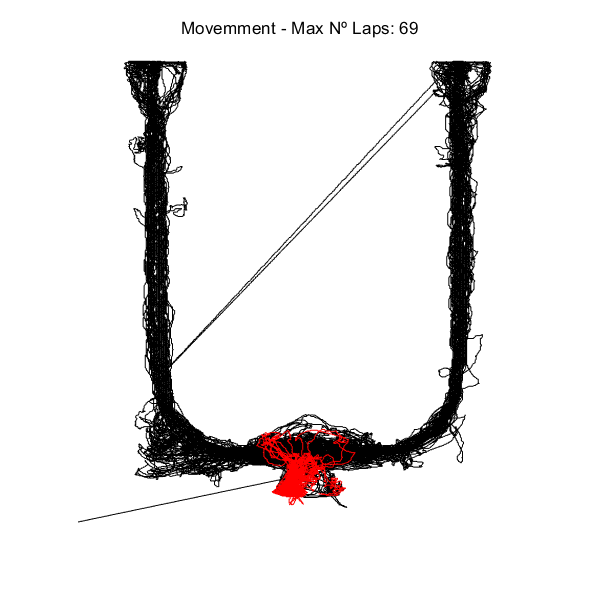

% Change values and click to update
 
% List of files
dbPathOne = "D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part1~/";
dbPathTwo = "D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part2~/";

filePaths = [dbPathOne; dbPathTwo];

% List all files in each directory
prePos = 2;         % Choose condition - Pre x Post
absolutFilePath = ls(fullfile(filePaths(prePos), '*.mat'));
nFiles = 4;    % Choose a file 1 - 10

% Load file with coordinates
tempXY = load(sprintf('%s%s', filePaths(prePos), absolutFilePath(nFiles,1:end)), 'Laps', 'Track');

fig = figure(1);clf
fig.Position = [0,0, 600, 600];

% Get coord.
nLaps = max(tempXY.Laps.lapID);
lap    = tempXY.Laps.NLapCW + tempXY.Laps.NLapCCW;
xcoord = tempXY.Track.xMM;
ycoord = tempXY.Track.yMM;
% Plot movimentation ( all )
plot(ycoord(20000:end),xcoord(20000:end),'k-')

% Select one lap ( lap == n )
tempX = [];
tempY = [];
for l=1:nLaps
   lapidx = lap == l;
   tempX = [tempX; xcoord(lapidx)];
   tempY = [tempY; ycoord(lapidx)];
end

hold on
sgtitle(sprintf('Movemment - Max Nº Laps: %i', nLaps))
plot(tempY,tempX,'r-')
xlim([0, 1100])
ylim([0, 1600])
hold off
axis square
set(gca, ...
        'Box',      'off',...
        'Visible', 'off') 

clearvars -except dataFull srate dt numReads numSubReads nData data dataUnorm fig

    % Change values and click to update
 
% List of files
dbPathOne = "D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part1~/";
dbPathTwo = "D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part2~/";

filePaths = [dbPathOne; dbPathTwo];

% List all files in each directory
prePos = 2;         % Choose condition - Pre x Post
absolutFilePath = ls(fullfile(filePaths(prePos), '*.mat'));
nFiles = 4;    % Choose a file 1 - 10

% Save plot
savePath = "D:/Ivan/Desktop/";
fileName = "mov1";
save = 0;
if save
    saveFile = sprintf('%s%s', savePath, fileName);
    saveas(fig, saveFile, 'epsc');
    saveas(fig, saveFile, 'png');
end
 

### LFP - One file at time

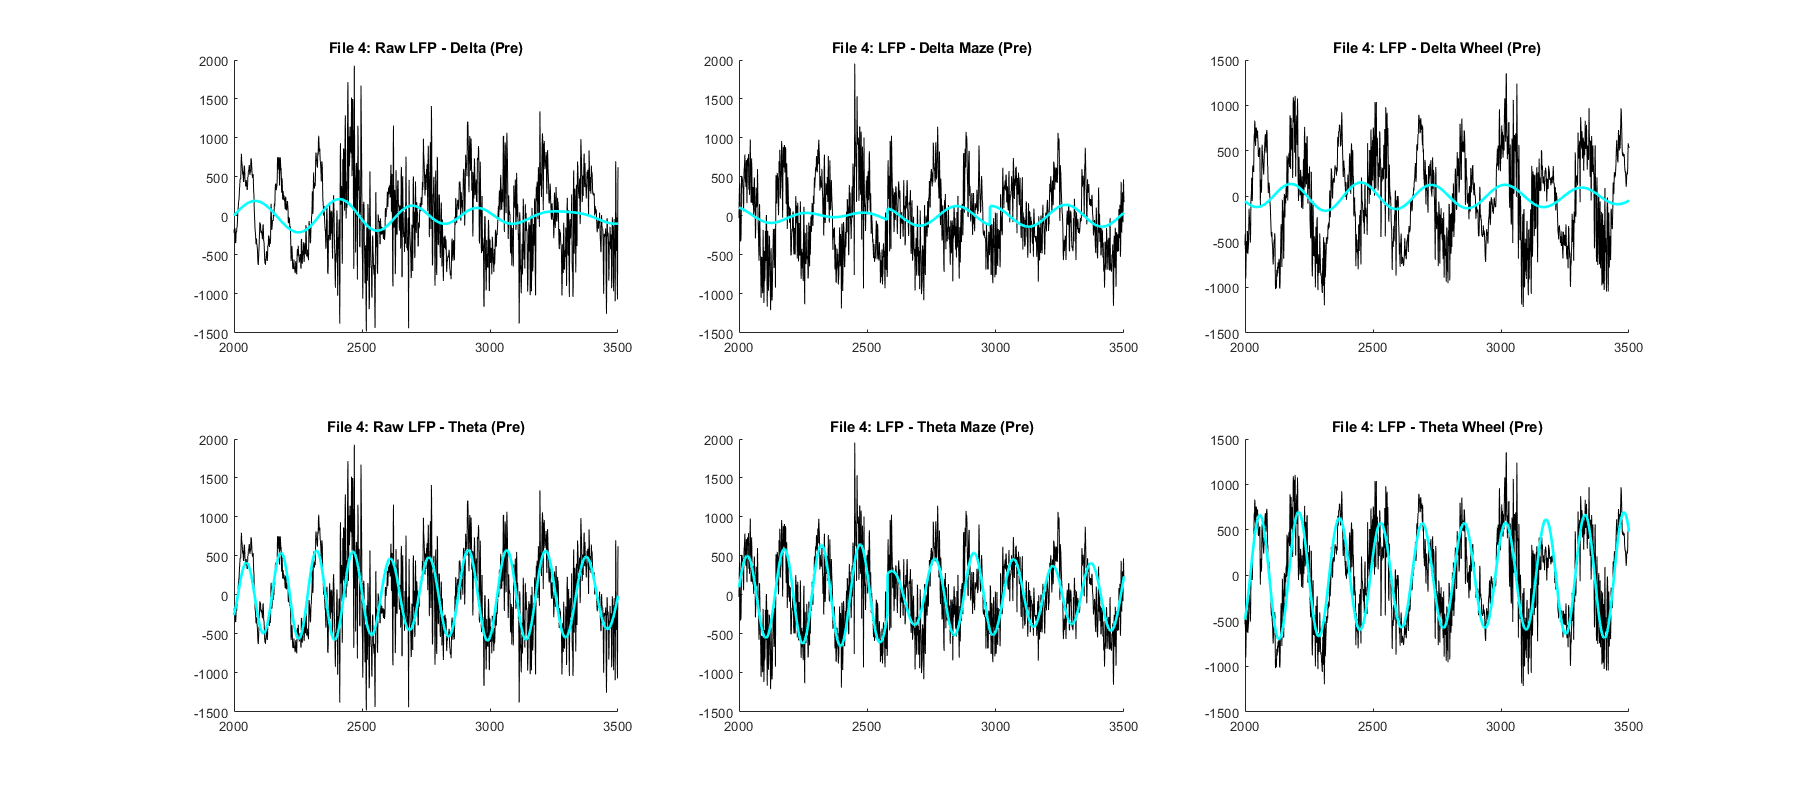

% Change values and click to update
 
        
% Pre or Post
prePost =1;
prePostKeys = ["Pre", "Post"];

% Data files 1 - 10
file = 4;
tempData = dataFull{prePost,file};

% Test Plots
fig = figure(1);clf
fig.Position = [0,0, 1800, 800];
xLim = [2000, 3500];

% a1 Raw LFP - Delta
subplot(2,3,1)
plotLFPSupplemental(tempData, file, "Delta", "None", 100, xLim)
title(sprintf('File %i: Raw LFP - Delta (%s)', file, prePostKeys(prePost)))

% a2 LFP - Delta Maze
subplot(2,3,2)
plotLFPSupplemental(tempData, file, "Delta", "Mz", 100, xLim)
title(sprintf('File %i: LFP - Delta Maze (%s)', file, prePostKeys(prePost)))

% a3 LFP - Delta Wheel
subplot(2,3,3)
plotLFPSupplemental(tempData, file, "Delta", "Wh", 100, xLim)
title(sprintf('File %i: LFP - Delta Wheel (%s)', file, prePostKeys(prePost)))

% a4 Raw LFP - Theta
subplot(2,3,4)
plotLFPSupplemental(tempData, file, "Theta", "None", 100, xLim)
title(sprintf('File %i: Raw LFP - Theta (%s)', file, prePostKeys(prePost)))

% a5 LFP - Delta Maze
subplot(2,3,5)
plotLFPSupplemental(tempData, file, "Theta", "Mz", 100, xLim)
title(sprintf('File %i: LFP - Theta Maze (%s)', file, prePostKeys(prePost)))

% a6 LFP - Delta Wheel
subplot(2,3,6)
plotLFPSupplemental(tempData, file, "Theta", "Wh", 100, xLim)
title(sprintf('File %i: LFP - Theta Wheel (%s)', file, prePostKeys(prePost)))

clearvars -except dataFull srate dt numReads numSubReads nData data dataUnorm fig

% Save plot
savePath = "filepath";
fileName = "newName.txt";
save = 0;
if save
    saveFile = sprintf('%s%s', savePath, fileName);
    saveas(fig, saveFile, 'epsc');
    saveas(fig, saveFile, 'png');
end
 

### PSD - Group

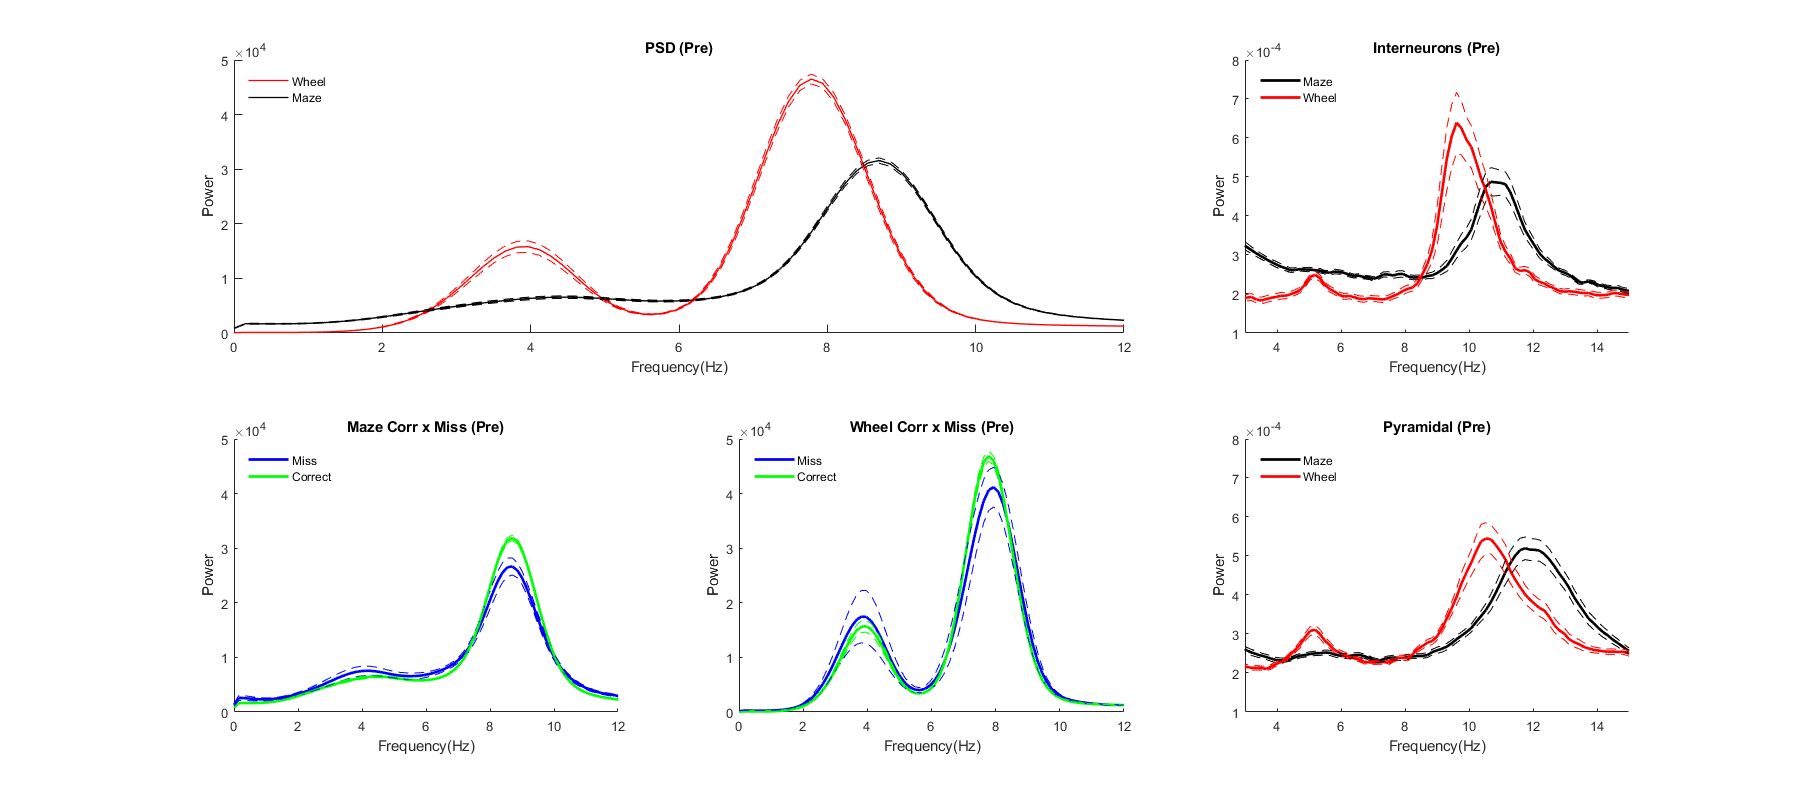

% Change values and click to update
 

%% Save/Load Data
if ~exist('dataUnorm')
    tic
    savePath = 'H:\.shortcut-targets-by-id\1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_\ProjetoWheelMaze\Dataset\DRYAD\Single Files';
    file = sprintf('%s/%s.mat', savePath, 'AcgPwelchData');
    load(file)
    toc
end

% Test Plots
fig = figure(1);clf
fig.Position = [0,0, 1800, 800];

% Run on value change
prePost = 1;
prePostKeys = ["Pre", "Post"];

dataStruct = {struct('Mz', [], 'Wh', [], 'nTrials' , 0), struct('Mz', [], 'Wh', [], 'nTrials' , 0)}; 
dataStructCM = {struct('Mz', [], 'Wh', [], 'nTrials' , 0), struct('Mz', [], 'Wh', [], 'nTrials' , 0)}; 
for i=1:numSubReads
    dataStruct{prePost}.nTrials  = dataStruct{prePost}.nTrials  + size(dataFull{prePost, i}.Choice, 1);
    
    dataTemp = dataFull{prePost, i}.Pwelch;
    
    dataStruct{prePost}.Mz = [dataStruct{prePost}.Mz; dataTemp.Psd.Mz];
    dataStruct{prePost}.Wh = [dataStruct{prePost}.Wh; dataTemp.Psd.Wh];
    
    % Select data for correct and missed trials
    for chc=1:2
        dataStructCM{chc}.nTrials = dataStructCM{chc}.nTrials + sum(dataFull{prePost, i}.Choice == chc-1);
        
        dataTemp = dataFull{prePost, i}.Pwelch;
        cMask = dataTemp.Choice == chc-1;
    
        dataStructCM{chc}.Wh = [dataStructCM{chc}.Wh; dataTemp.Psd.Wh(cMask, :)];
        dataStructCM{chc}.Mz = [dataStructCM{chc}.Mz; dataTemp.Psd.Mz(cMask, :)];
    end
end

x = dataTemp.Frequency;
% a1 Full PSD
subplot(2,3, [1, 2])
plotPSD(x, dataStruct{prePost}.Wh, dataStruct{prePost}.Mz, dataStruct{prePost}.nTrials, dataStruct{prePost}.nTrials, ["Wheel", "Maze"], sprintf('PSD (%s)', prePostKeys(prePost)), ['r', 'k'], 1, [0 , 5e4], [0,12], 'Power', 'Frequency(Hz)', 0)

% a2 Interneuron
subplot(2,3, 3)
value = 0.2;
limMzInt=find(mean(data{prePost}.Mz.Acg.Int,2)>value);
limWhInt=find(mean(data{prePost}.Wh.Acg.Int,2)>value);
plotPSD(dataUnorm{prePost}.PwelchF, data{prePost}.Mz.Pwelch.Int(limMzInt,:), data{prePost}.Wh.Pwelch.Int(limWhInt,:), size(data{prePost}.Mz.Pwelch.Int(limMzInt,:),1),...
    size(data{prePost}.Wh.Pwelch.Int(limWhInt,:),1), ["Maze", "Wheel"], sprintf('Interneurons (%s)', prePostKeys(prePost)), ['k', 'r'], 2, [1e-4, 8e-4], [3, 15], 'Power', 'Frequency(Hz)', 0)

% a3 Correct x Miss - Maze
subplot(2,3, 4)
plotPSD(x, dataStructCM{1}.Mz, dataStructCM{2}.Mz, dataStructCM{1}.nTrials, dataStructCM{2}.nTrials, ["Miss", "Correct"], sprintf('Maze Corr x Miss (%s)', prePostKeys(prePost)), ['b', 'g'], 2, [0, 5e4], [0, 12], 'Power', 'Frequency(Hz)', 0);

% a4 Correct x Miss - Wheel
subplot(2,3, 5)
plotPSD(x, dataStructCM{1}.Wh, dataStructCM{2}.Wh, dataStructCM{1}.nTrials, dataStructCM{2}.nTrials, ["Miss", "Correct"], sprintf('Wheel Corr x Miss (%s)', prePostKeys(prePost)), ['b', 'g'], 2, [0, 5e4], [0, 12], 'Power', 'Frequency(Hz)', 0);

% a5 Pyramidal
subplot(2,3, 6)
limMzPyr=find(mean(data{prePost}.Mz.Acg.Pyr,2)>value);
limWhPyr=find(mean(data{prePost}.Wh.Acg.Pyr,2)>value);
plotPSD(dataUnorm{prePost}.PwelchF, data{prePost}.Mz.Pwelch.Pyr(limMzPyr,:), data{prePost}.Wh.Pwelch.Pyr(limWhPyr,:), size(data{prePost}.Mz.Pwelch.Pyr(limMzPyr,:),1),...
    size(data{prePost}.Wh.Pwelch.Pyr(limWhPyr,:),1), ["Maze", "Wheel"], sprintf('Pyramidal (%s)', prePostKeys(prePost)), ['k', 'r'], 2, [1e-4, 8e-4], [3, 15], 'Power', 'Frequency(Hz)', 0)

clearvars -except dataFull srate dt numReads numSubReads nData data dataUnorm fig

% Save plot
savePath = "filepath";
fileName = "newName.txt";
save = 0;
if save
    saveFile = sprintf('%s%s', savePath, fileName);
    saveas(fig, saveFile, 'epsc');
end
 

### ACG - Group

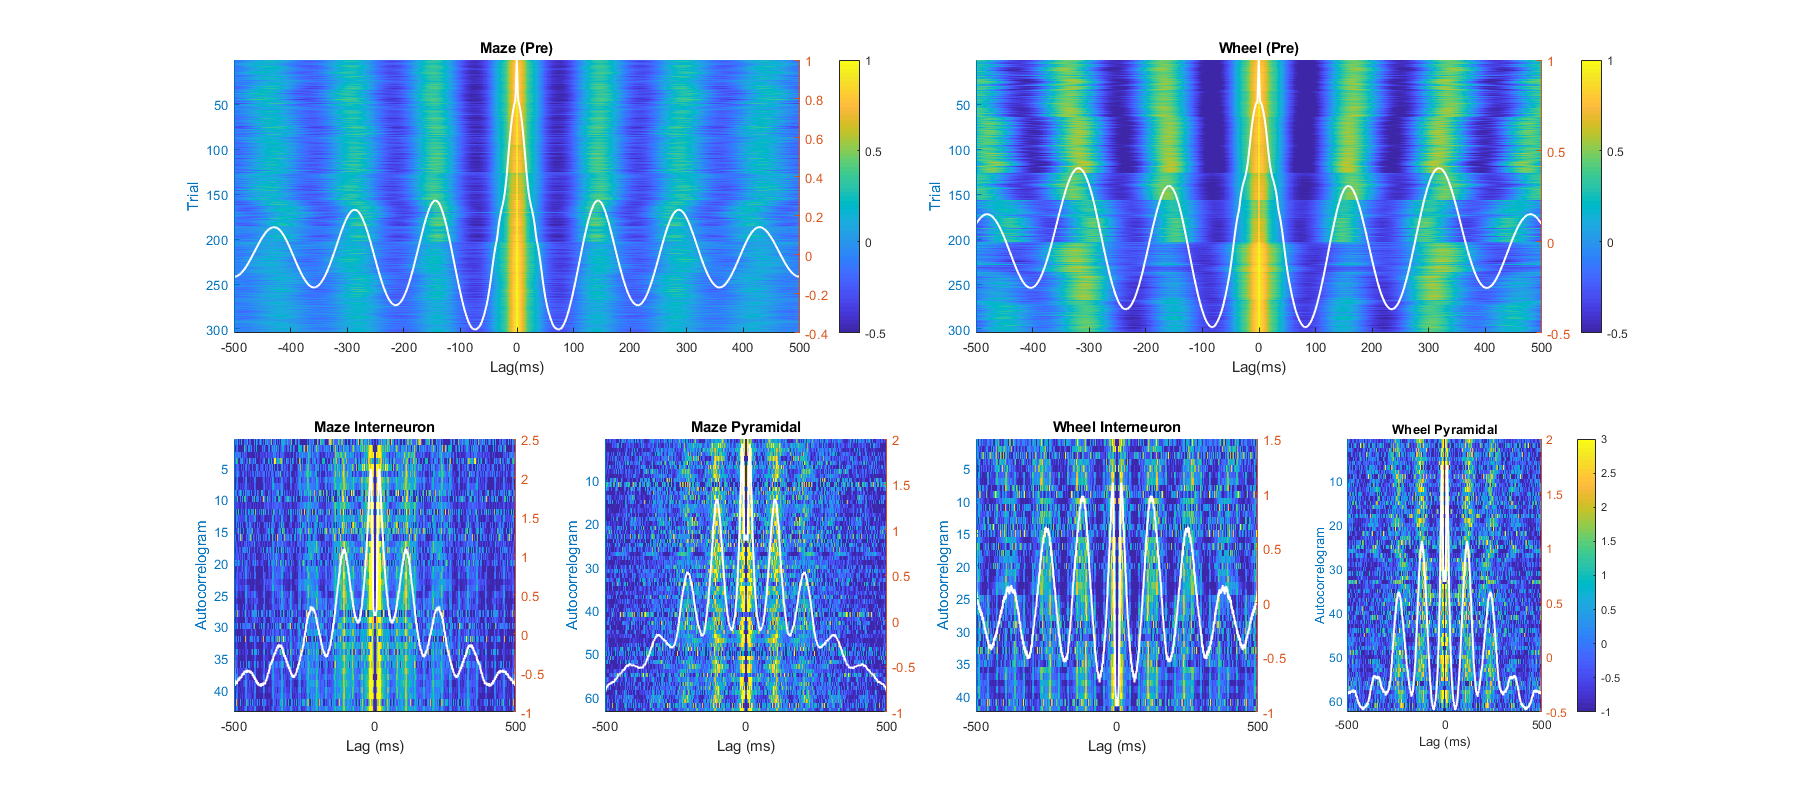

% Change values and click to update
 

prePost = 1;
prePostKeys = ["Pre", "Post"];

auxMzAcgCombine = [];
auxWhAcgCombine = [];
for i=1:numSubReads
    dataTemp = dataFull{prePost, i};
    
    laps = size(dataTemp.Choice, 1);
    for lp=1:laps

        mzMask = dataTemp.Speed.Mz{lp} > 100;
        whMask = dataTemp.Speed.Wh{lp} > 100;

        LFPMz = dataTemp.Lfp{lp}(mzMask);
        LFPWh = dataTemp.Lfp{lp}(whMask);

        % Capture snippet
        [acgMz, lagsMz] = xcorr(LFPMz,'coef', 500);    
        [acgWh, lagsWh] = xcorr(LFPWh,'coef', 500);    

        auxMzAcgCombine = [auxMzAcgCombine, acgMz];
        auxWhAcgCombine = [auxWhAcgCombine, acgWh];
    end
end
fig = figure(1); clf
fig.Position = [0,0, 1800, 800];
% a1
subplot(2,4,[1,2])
val = size(auxMzAcgCombine, 1)/2;
xLimValue = -val:val-1;
plotImagesc(lagsMz, auxMzAcgCombine', xLimValue, sprintf('Maze (%s)', prePostKeys(prePost)), [-500,500], 'Trial', 'Lag(ms)', 1, [-0.5, 1], 0, 0)

% a2
subplot(2,4,[3,4])
plotImagesc(lagsWh, auxWhAcgCombine', xLimValue, sprintf('Wheel (%s)', prePostKeys(prePost)), [-500,500], 'Trial', 'Lag(ms)', 1, [-0.5, 1], 0, 0)

% a3
value=0.2;
sm=20;
subplot(2,4,5)

% axis values
yVal = data{prePost}.Mz.Acg.Int;
xHalf = floor(size(yVal,2)/2);
xVal = -xHalf:10:xHalf;
lim = find(mean(yVal,2)>value);
combine = zscore(yVal(lim,:),[],2);

plotImagesc(xVal, combine, dataUnorm{prePost}.AcgLags, 'Maze Interneuron', 0, 'Autocorrelogram', 'Lag (ms)', 0, [-1,3], sm, 0)
% a3
subplot(2,4,6)

% axis values
yVal = data{prePost}.Mz.Acg.Pyr;
xHalf = floor(size(yVal,2)/2);
xVal = -xHalf:10:xHalf;
lim = find(mean(yVal,2)>value);
combine = zscore(yVal(lim,:),[],2);

plotImagesc(xVal, combine, dataUnorm{prePost}.AcgLags, 'Maze Pyramidal', 0, 'Autocorrelogram', 'Lag (ms)', 0, [-1,3], sm, 0)
% a3
subplot(2,4,7)

% axis values
yVal = data{prePost}.Wh.Acg.Int;
xHalf = floor(size(yVal,2)/2);
xVal = -xHalf:10:xHalf;
lim = find(mean(yVal,2)>value);
combine = zscore(yVal(lim,:),[],2);

plotImagesc(xVal, combine, dataUnorm{prePost}.AcgLags, 'Wheel Interneuron', 0, 'Autocorrelogram', 'Lag (ms)', 0, [-1,3], sm, 0)
% a3
subplot(2,4,8)

% axis values
yVal = data{prePost}.Wh.Acg.Pyr;
xHalf = floor(size(yVal,2)/2);
xVal = -xHalf:10:xHalf;
lim = find(mean(yVal,2)>value);
combine = zscore(yVal(lim,:),[],2);

plotImagesc(xVal, combine, dataUnorm{prePost}.AcgLags, 'Wheel Pyramidal', 0, 'Autocorrelogram', 'Lag (ms)', 1, [-1,3], sm, 0)

clearvars -except dataFull srate dt numReads numSubReads nData data dataUnorm fig

% Save plot
savePath = "filepath";
fileName = "newName.txt";
save = 0;
if save
    saveFile = sprintf('%s%s', savePath, fileName);
    saveas(fig, saveFile, 'epsc');
end
 

### Statistic

#### Miss and Hits Proportion - Single file

respStruct = repmat("", 10, 3);
respCell{1} =  zeros(10,2);
respCell{2} =  zeros(10,2);
[numReads, numSubReads ] = size(dataFull);

for nData=1:numReads
    for i=1:numSubReads
        
        dataTemp = dataFull{nData, i};
        choice = dataTemp.Choice;
        
        [count, value] = groupcounts(choice);
        
        if length(value) == 1
            if value == 0
                count = [count, 0];
                value = [value, 1];
            else
                count = [0, count];
                value = [0, value];
            end
        end
        err = (count(1)/sum(count))*100;
        hit = (count(2)/sum(count))*100;
        
        respCell{nData}(i, 1) =  err;
        respCell{nData}(i, 2) =  hit;
        if nData == 1
            respStruct(i, 1) = dataTemp.Name(1:13);
            respStruct(i, 2) = sprintf('Hits Freq: %i/%i = %.2f - Miss Freq: %i/%i = %.2f', count(2), sum(count), hit, count(1), sum(count), err);
        else
            respStruct(i, 3) = sprintf('Hits Freq: %i/%i = %.2f - Miss Freq: %i/%i = %.2f', count(2), sum(count), hit, count(1), sum(count), err);
        end        
    end
end

array2table(respStruct, 'VariableNames', {'FileName', 'Pre', 'Post'})

ans = 10×3 table
       FileName                                Pre                                                     Post                         
    _______________    ____________________________________________________    _____________________________________________________
    "A498-20120807"    "Hits Freq: 30/33 = 90.91 - Miss Freq: 3/33 = 9.09"     "Hits Freq: 31/53 = 58.49 - Miss Freq: 22/53 = 41.51"
    "A498-20120809"    "Hits Freq: 30/30 = 100.00 - Miss Freq: 0/30 = 0.00"    "Hits Freq: 50/67 = 74.63 - Miss Freq: 17/67 = 25.37"
    "A498-20120813"    "Hits Freq: 30/32 = 93.75 - Miss Freq: 2/32 = 6.25"     "Hits Freq: 9/44 = 20.45 - Miss Freq: 35/44 = 79.55" 
    "A498-20120815"    "Hits Freq: 30/31 = 96.77 - Miss Freq: 1/31 = 3.23"     "Hits Freq: 50/69 = 72.46 - Miss Freq: 19/69 = 27.54"
    "A498-20120827"    "Hits Freq: 30/30 = 100.00 - Miss Freq: 0/30 = 0.00"    "Hit

#### Miss and Hits Proportion - Group Plot

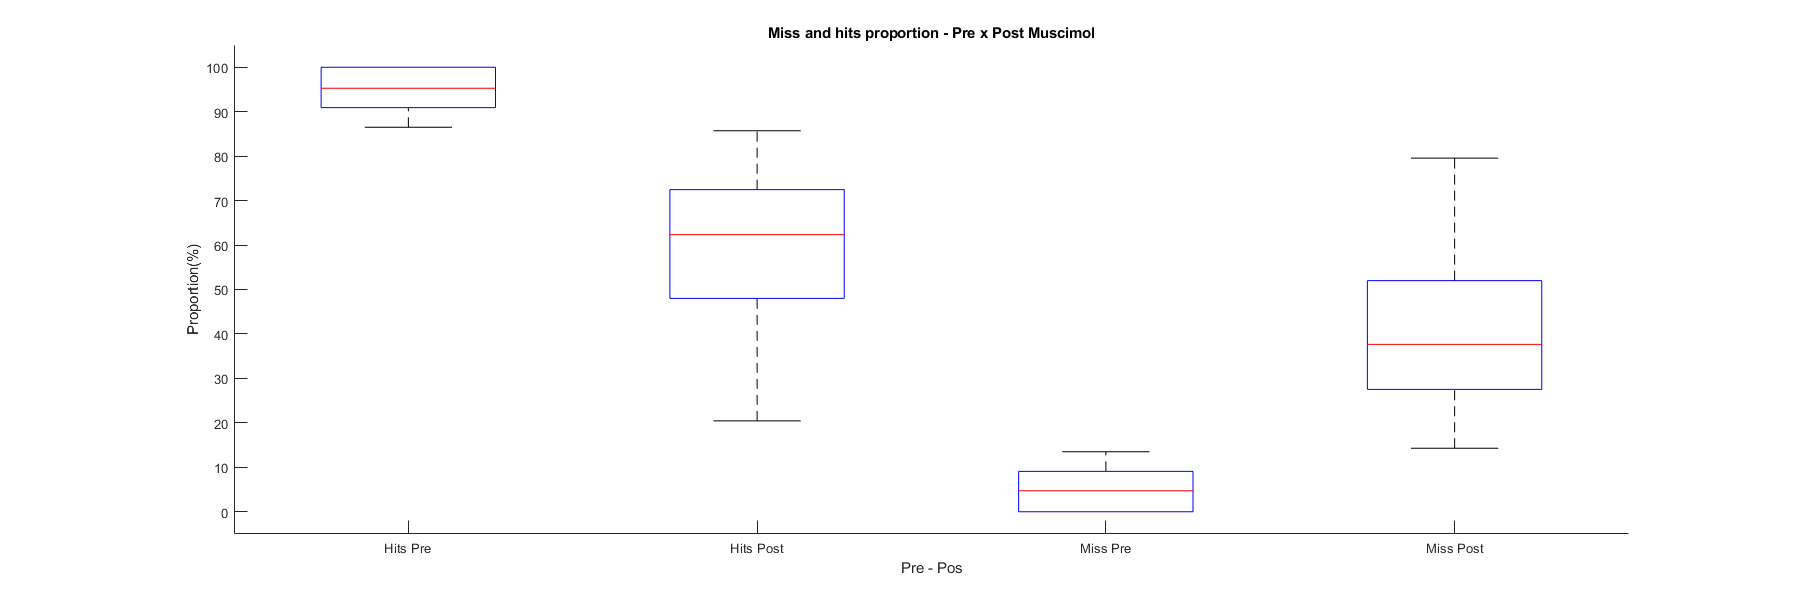

fig = figure(1); clf
fig.Position = [0, 0, 1800, 600];
plotBoxPlot({respCell{1}(:,2), respCell{2}(:,2), respCell{1}(:,1), respCell{2}(:,1)}, ["Hits Pre","Hits Post", "Miss Pre","Miss Post"], "Proportion(%)", "Pre - Pos", "Miss and hits proportion - Pre x Post Muscimol", [])

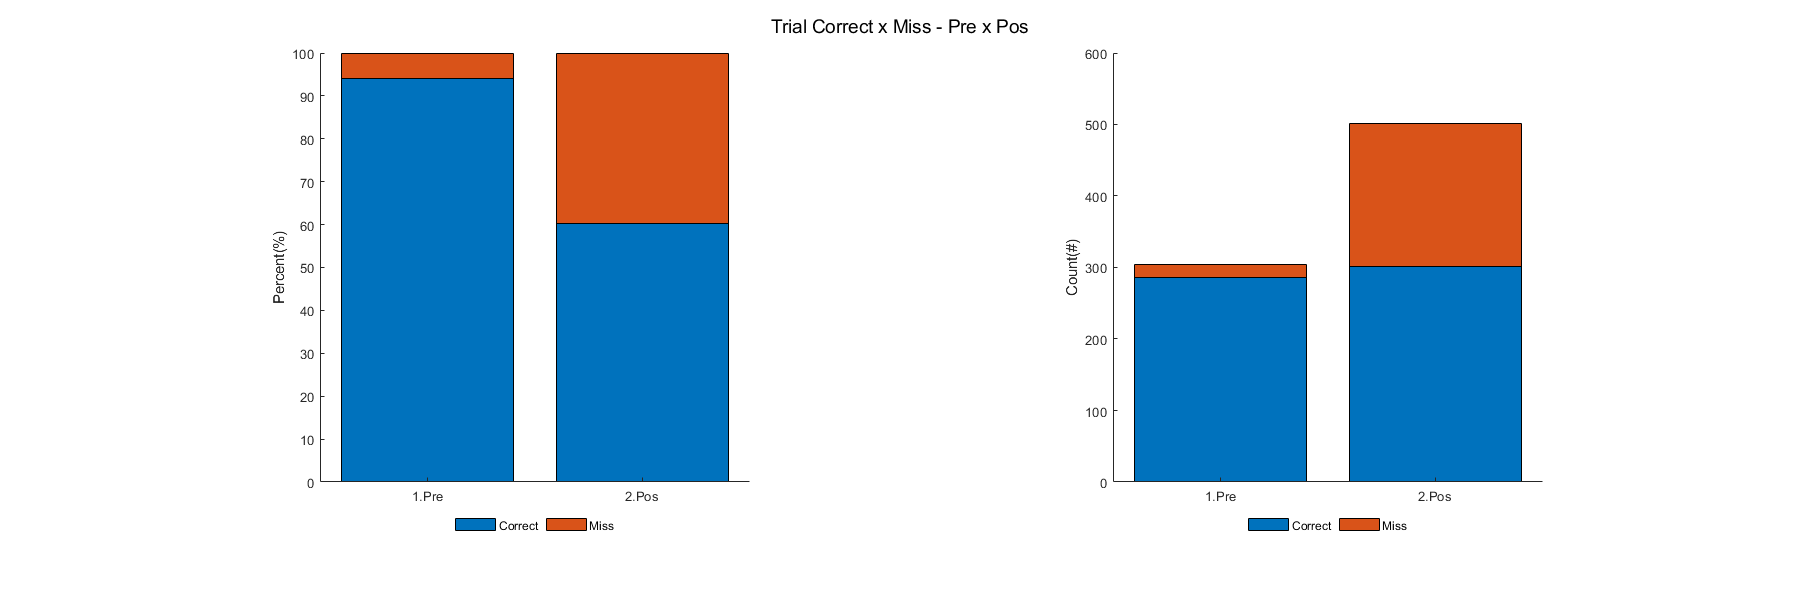

trialsToStack = [];
normTrialsToStack = zeros(2);
for nData=1:2
    sumTrials = struct('Corr', 0, 'Miss', 0);
    for n=1:10
        aux = dataFull{nData, n}.Choice;
        mss = sum(aux == 0);
        crr = sum(aux == 1);
    
        sumTrials.Corr = sumTrials.Corr + crr;
        sumTrials.Miss = sumTrials.Miss + mss;
    end
    trialsToStack(nData, 1) = sumTrials.Corr;    
    trialsToStack(nData, 2) = sumTrials.Miss;
    normTrialsToStack(nData, :) = (trialsToStack(nData, :)/sum(trialsToStack(nData, :)))*100;
end

fig = figure(2); clf
fig.Position = [0, 0, 1800, 600];

sgtitle( 'Trial Correct x Miss - Pre x Pos' )
subplot(1,2,1)
cat = categorical({'1.Pre','2.Pos'});
bar(cat, normTrialsToStack, 'stacked')
label1{1} = 'Correct';
label1{2} = 'Miss';
box off
legend(label1,'location','bestoutside','orientation','horizontal')
legend('boxoff')
ylabel 'Percent(%)'
box off
axis square

subplot(1,2,2)
cat = categorical({'1.Pre','2.Pos'});
bar(cat, trialsToStack, 'stacked')
label1{1} = 'Correct';
label1{2} = 'Miss';
box off
legend(label1,'location','bestoutside','orientation','horizontal')
legend('boxoff')
ylabel 'Count(#)'
box off
axis square

clearvars -except dataFull srate dt numReads numSubReads nData data dataUnorm fig

#### Time Spent

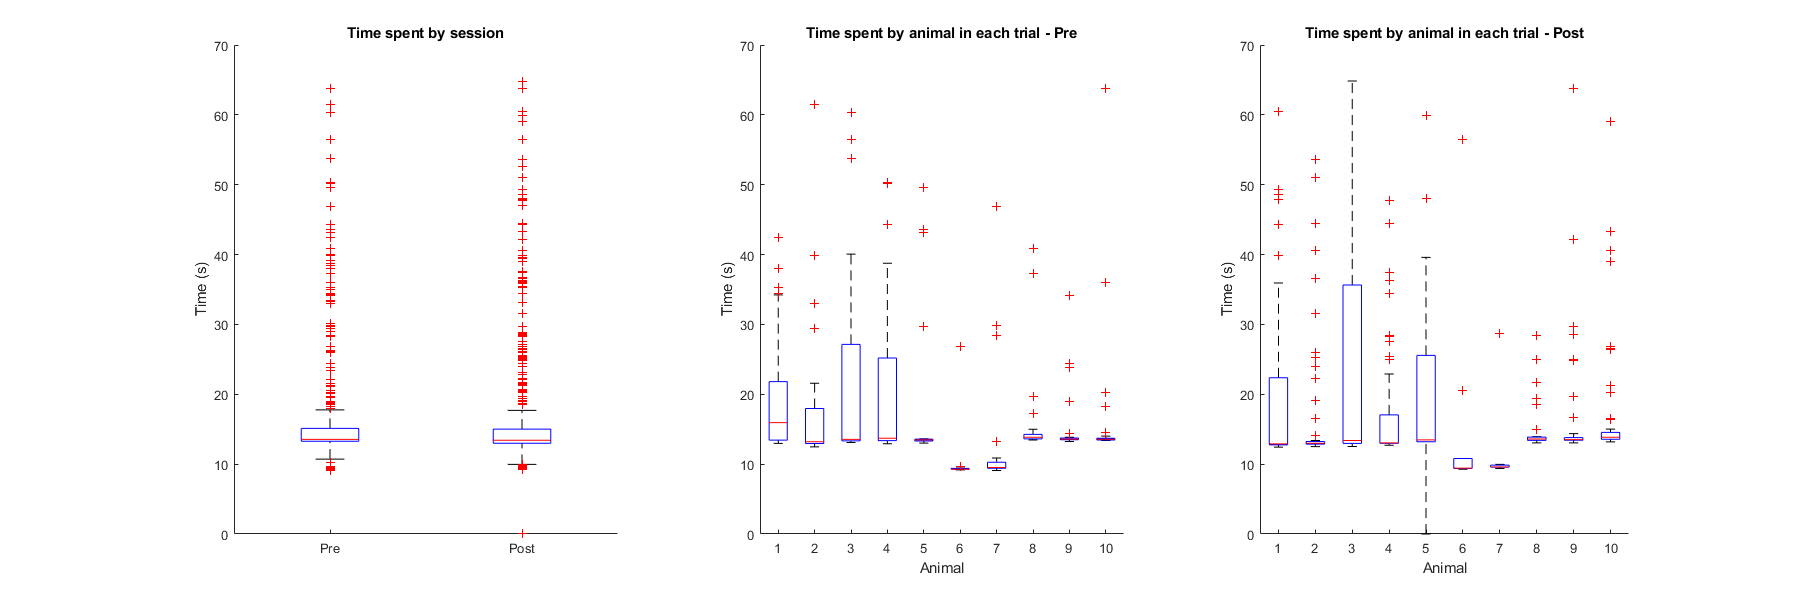

% Change values and click to update
 
% List of files
dbPathOne = "D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part1~/";
dbPathTwo = "D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part2~/";

filePaths = [dbPathOne; dbPathTwo];

totalTime = struct('Pre', [], 'Post', [], 'TagPre', [], 'TagPost', []);

for prePos=1:2
    absolutFilePath = ls(fullfile(filePaths(prePos), '*.mat'));
    numReads = size(absolutFilePath, 1);
    
    for nData=1:numReads
        dataTemp = load(sprintf('%s%s', filePaths(prePos), absolutFilePath(nData,1:end)), 'Laps');
        laps = unique(dataTemp.Laps.lapID);
        timeLaps = zeros(1, max(laps));
               
        for lp=1:max(laps)
            lapMask = (dataTemp.Laps.NLapCW + dataTemp.Laps.NLapCCW) == lp;

            trialDuraction = sum(lapMask)/srate;
            timeLaps(lp) = trialDuraction;
        end
        
        if prePos == 1
            totalTime.Pre = [totalTime.Pre, timeLaps];
            totalTime.TagPre = [totalTime.TagPre, repmat(nData, 1, length(timeLaps))];
        else
            totalTime.Post = [totalTime.Post, timeLaps];
            totalTime.TagPost = [totalTime.TagPost, repmat(nData, 1, length(timeLaps))];
        end
        
    end
end

fig = figure(1); clf
fig.Position = [0, 0, 1800, 600];

subplot(1,3,1)
tag = [repmat("Pre", 1, length(totalTime.Pre)), repmat("Post", 1, length(totalTime.Post))];
boxplot([totalTime.Pre, totalTime.Post], tag);
title('Time spent by session')
ylim([0, 70])
ylabel('Time (s)')
set(gca, ...
        'Box',      'off')
    
subplot(1,3,2)
boxplot(totalTime.Pre, totalTime.TagPre);
title('Time spent by animal in each trial - Pre')
ylim([0, 70])
ylabel('Time (s)')
xlabel('Animal')
set(gca, ...
        'Box',      'off')

subplot(1,3,3)
boxplot(totalTime.Post, totalTime.TagPost);
title('Time spent by animal in each trial - Post')
ylim([0, 70])
ylabel('Time (s)')
xlabel('Animal')
set(gca, ...
        'Box',      'off')

sprintf('Total Pre:\n\tMean:\t%.2f sec\n\tMedian: %.2f sec\nTotal Post:\n\tMean:\t%.2f sec\n\tMedian: %.2f sec', mean(totalTime.Pre), median(totalTime.Pre), mean(totalTime.Post), median(totalTime.Post))

ans =     'Total Pre:
     	Mean:	17.48 sec
     	Median: 13.54 sec
     Total Post:
     	Mean:	24.00 sec
     	Median: 13.43 sec'

clearvars -except dataFull srate dt numReads numSubReads nData data dataUnorm fig

#### Mean PSD - Miss x Hit

bands = [3,5; 6,10];
bandKeys = ["4-Hz", "Theta"];
respCell{1, 1} =  zeros(2,6);
respCell{1, 2} =  zeros(2,6);
respCell{2, 1} =  zeros(2,6);
respCell{2, 2} =  zeros(2,6);
dataResp = {};

for bnd=1:length(bands)
    dataStruct = {struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', []), struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', [])}; 

    for nData=1:numReads
        nTrials = 0;
        for i=1:numSubReads
            dataTemp = dataFull{nData, i}.Pwelch;
            nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

            mzPsdC = [];
            mzPsdE = [];
            frq = [];
            whPsdC = [];
            whPsdE = [];

            fMask = ( dataTemp.Frequency  > bands(bnd,1) ) & ( dataTemp.Frequency  < bands(bnd,2));
            cMask = dataTemp.Choice == 0;

            dataStruct{nData}.MzC = [dataStruct{nData}.MzC; dataTemp.Psd.Mz(~cMask, fMask)];
            dataStruct{nData}.WhC = [dataStruct{nData}.WhC; dataTemp.Psd.Wh(~cMask, fMask)];
            dataStruct{nData}.MzE = [dataStruct{nData}.MzE; dataTemp.Psd.Mz(cMask, fMask)];
            dataStruct{nData}.WhE = [dataStruct{nData}.WhE; dataTemp.Psd.Wh(cMask, fMask)];
        end
        dataResp{bnd, nData} = dataStruct;
        key = "Pre";
        if nData == 2
            key = "Pos";
        end

        x = mean(dataStruct{nData}.Freq, 2);
        meanWhC = mean(dataStruct{nData}.WhC,2);
        meanMzC = mean(dataStruct{nData}.MzC,2);
        meanWhE = mean(dataStruct{nData}.WhE,2);
        meanMzE = mean(dataStruct{nData}.MzE,2);

        % Std  
        stdWhC = std(meanWhC)/sqrt(nTrials);
        stdMzC = std(meanMzC)/sqrt(nTrials);
        stdWhE = std(meanWhE)/sqrt(nTrials);
        stdMzE = std(meanMzE)/sqrt(nTrials);

        [h, p, w] = swtest([meanMzC; meanMzE]);
        
        if h == 1
            [ pMz, hMz ] = ranksum(meanMzC, meanMzE);
        else
            [ hMz, pMz ] = ttest2(meanMzC, meanMzE);
        end
        [h, p, w] = swtest([meanWhC; meanWhE]);
        if h == 1
            [ pWh, hWh ] = ranksum(meanWhC, meanWhE);
        else
            [ hWh, pWh ] = ttest2(meanWhC, meanWhE);
        end
        respCell{bnd, nData}(1, 1) = mean(meanMzC);
        respCell{bnd, nData}(1, 2) = mean(meanMzE);
        respCell{bnd, nData}(1, 3) = hMz;
        respCell{bnd, nData}(1, 4) = pMz;
        respCell{bnd, nData}(1, 5) = stdMzC;
        respCell{bnd, nData}(1, 6) = stdMzE;
        
        respCell{bnd, nData}(2, 1) = mean(meanWhC);
        respCell{bnd, nData}(2, 2) = mean(meanWhE);
        respCell{bnd, nData}(2, 3) = hWh;
        respCell{bnd, nData}(2, 4) = pWh;
        respCell{bnd, nData}(2, 5) = stdWhC;
        respCell{bnd, nData}(2, 6) = stdWhE;
    end
    
    preData = array2table(respCell{1}, 'VariableNames', {'Mz_Hit', 'Mz_Miss', 'h', 'p_value', 'Std_Mz_Hit', 'Std_Mz_Miss'});
    postData = array2table(respCell{2}, 'VariableNames', {'Mz_Hit', 'Mz_Miss', 'h', 'p_value', 'Std_Mz_Hit', 'Std_Mz_Miss'});
    sprintf("%s - Mean PSD - Pre", bandKeys(bnd))
    preData
    sprintf("%s - Mean PSD - Post", bandKeys(bnd))
    postData
end

ans = "4-Hz - Mean PSD - Pre"

preData = 2×6 table
    Mz_Hit    Mz_Miss    h    p_value     Std_Mz_Hit    Std_Mz_Miss
    ______    _______    _    ________    __________    ___________
    6007.8    7007.5     0    0.064589      224.35        185.98   
     12191     13730     0      0.2576      771.21        849.24   

ans = "4-Hz - Mean PSD - Post"

postData = 2×6 table
    Mz_Hit    Mz_Miss    h    p_value    Std_Mz_Hit    Std_Mz_Miss
    ______    _______    _    _______    __________    ___________
      0          0       0       0           0              0     
      0          0       0       0           0              0     

ans = "Theta - Mean PSD - Pre"

preData = 2×6 table
    Mz_Hit    Mz_Miss    h    p_value     Std_Mz_Hit    Std_Mz_Miss
    ______    _______    _    ________    __________    ___________
    6007.8    7007.5     0    0.064589      224.35        185.98   
     12191     13730     0      0.2576      771.21        849.24   

ans = "Theta - Mean PSD - Post"

postData = 2×6 table
    Mz_Hit    Mz_Miss    h    p_value     Std_Mz_Hit    Std_Mz_Miss
    ______    _______    _    ________    __________    ___________
    17681      16070     1    0.025591      184.55        152.11   
    22551      21276     0     0.33811      261.81        292.12   

#### Mean PSD - Miss x Hit - Bar Plot 

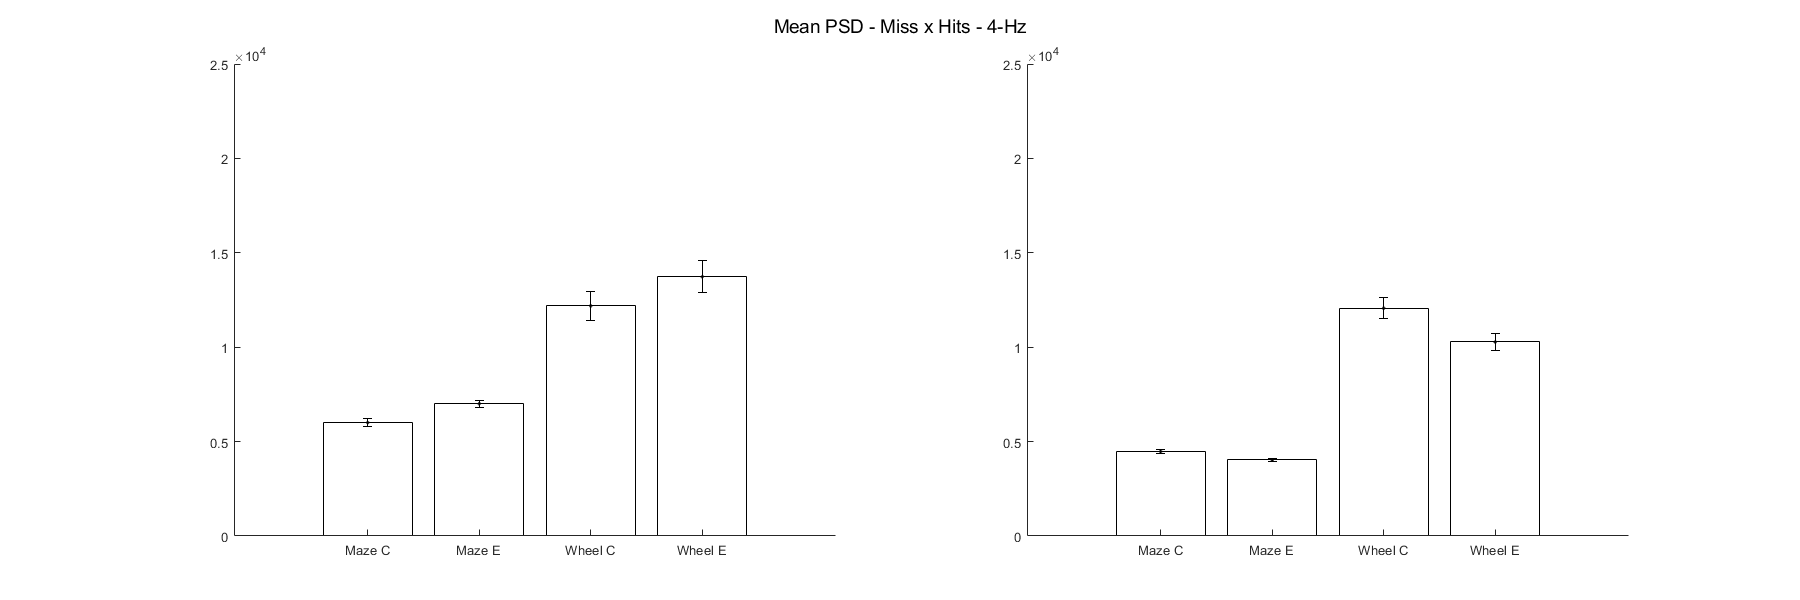

% Change values and click to update
 

bnd = 1;
fig = figure(1); clf
fig.Position = [1 1 1800 600];
sgtitle(sprintf("Mean PSD - Miss x Hits - %s", bandKeys(bnd)))
yLim = 25000;

subplot(1,2,1);
dataTemp = respCell{bnd, 1};
bar([1,2,3,4], [dataTemp(1,1), dataTemp(1,2), dataTemp(2,1), dataTemp(2,2)], 'w')
ylim([0, yLim])
hold on
errorbar([1,2,3,4], [dataTemp(1,1), dataTemp(1,2), dataTemp(2,1), dataTemp(2,2)], [dataTemp(1,5), dataTemp(1,6), dataTemp(2,5), dataTemp(2,6)], 'k.')        
box off
xticklabels(["Maze C", "Maze E", "Wheel C", "Wheel E"])

subplot(1,2,2);
dataTemp = respCell{bnd, 2};
bar([1,2,3,4], [dataTemp(1,1), dataTemp(1,2), dataTemp(2,1), dataTemp(2,2)], 'w')
ylim([0, yLim])
hold on
errorbar([1,2,3,4], [dataTemp(1,1), dataTemp(1,2), dataTemp(2,1), dataTemp(2,2)], [dataTemp(1,5), dataTemp(1,6), dataTemp(2,5), dataTemp(2,6)], 'k.')        
box off
xticklabels(["Maze C", "Maze E", "Wheel C", "Wheel E"])

#### PSD Peak - X.2

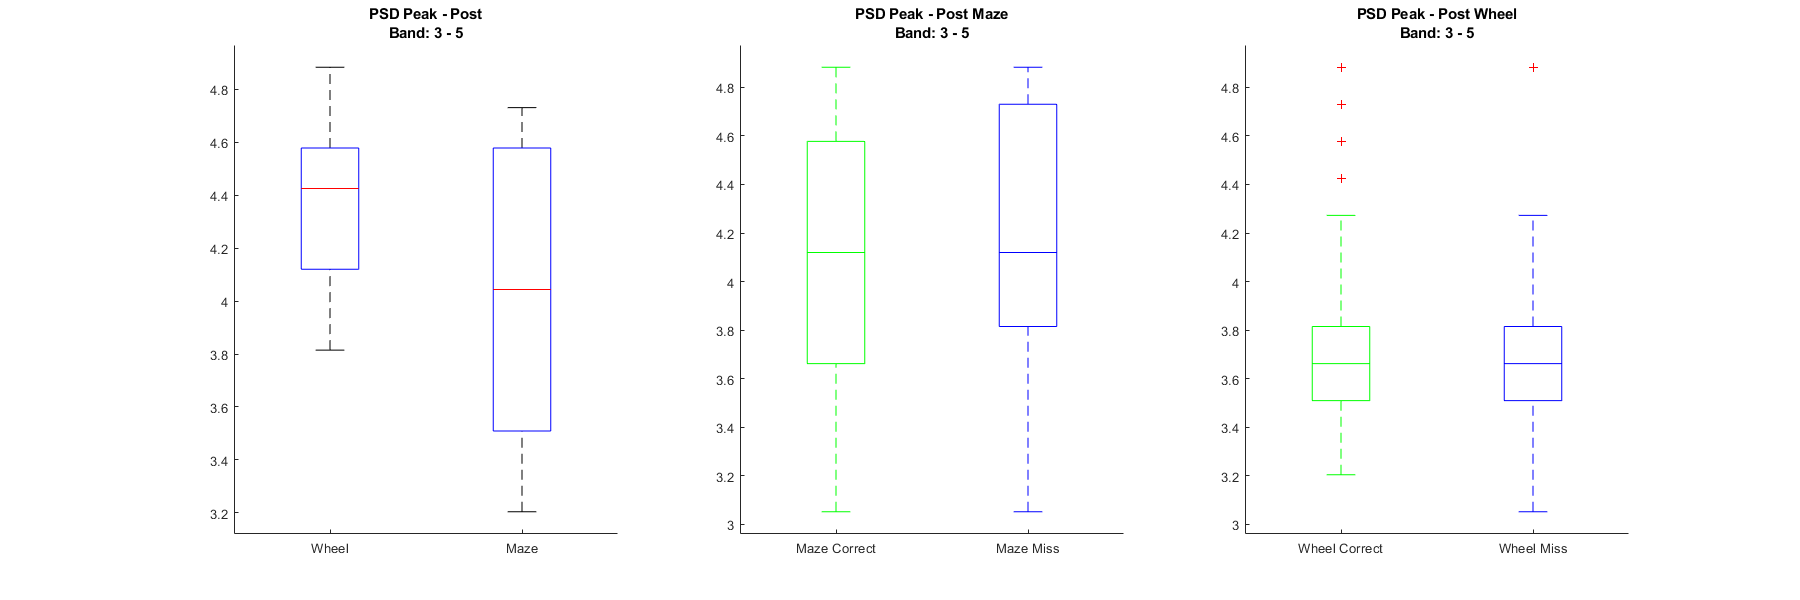

% Change values and click to update
 

prePos = 2;
prePosKeys = ["Pre", "Post"];
% 4-Hz: 3-5
% Theta: 6-10
band = [3, 5];

lvlZero = struct('Mz', [], 'Wh', [], 'MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', []);
data = {lvlZero, lvlZero}; 
    
for i=1:numSubReads
    dataTemp = dataFull{prePos, i}.Pwelch;

    fMask = ( dataTemp.Frequency  > band(1) ) & ( dataTemp.Frequency  < band(2));
    cMask = dataTemp.Choice == 0;

    data{prePos}.Mz = [data{prePos}.Mz; dataTemp.Psd.Mz(fMask)];
    data{prePos}.Wh = [data{prePos}.Wh; dataTemp.Psd.Wh(fMask)];
    
    data{prePos}.MzC = [data{prePos}.MzC; dataTemp.Psd.Mz(~cMask, fMask)];
    data{prePos}.WhC = [data{prePos}.WhC; dataTemp.Psd.Wh(~cMask, fMask)];
    data{prePos}.MzE = [data{prePos}.MzE; dataTemp.Psd.Mz(cMask, fMask)];
    data{prePos}.WhE = [data{prePos}.WhE; dataTemp.Psd.Wh(cMask, fMask)];

end
fig = figure(1); clf
fig.Position = [0, 0, 1800, 600];

subplot(1,3,1);
peakMz = getPeakVal(data{prePos}.Mz', dataTemp.Frequency(fMask));
peakWh = getPeakVal(data{prePos}.Wh', dataTemp.Frequency(fMask));

plotBoxPlot({peakMz, peakWh}, ["Wheel", "Maze"], [], [], sprintf('PSD Peak - %s\nBand: %i - %i', prePosKeys(prePos), band(1), band(2)), [])

subplot(1,3,2);
peakMzC = getPeakVal(data{prePos}.MzC', dataTemp.Frequency(fMask));
peakWhC = getPeakVal(data{prePos}.WhC', dataTemp.Frequency(fMask));
peakMzE = getPeakVal(data{prePos}.MzE', dataTemp.Frequency(fMask));
peakWhE = getPeakVal(data{prePos}.WhE', dataTemp.Frequency(fMask));

plotBoxPlot({peakMzC, peakMzE}, ["Maze Correct", "Maze Miss"], [], [], sprintf('PSD Peak - %s Maze\nBand: %i - %i', prePosKeys(prePos), band(1), band(2)), ['g', 'b'])

subplot(1,3,3);
plotBoxPlot({peakWhC, peakWhE}, ["Wheel Correct", "Wheel Miss"], [], [], sprintf('PSD Peak - %s Wheel\nBand: %i - %i', prePosKeys(prePos), band(1), band(2)), ['g', 'b'])

#### Correlation - Scatterplot

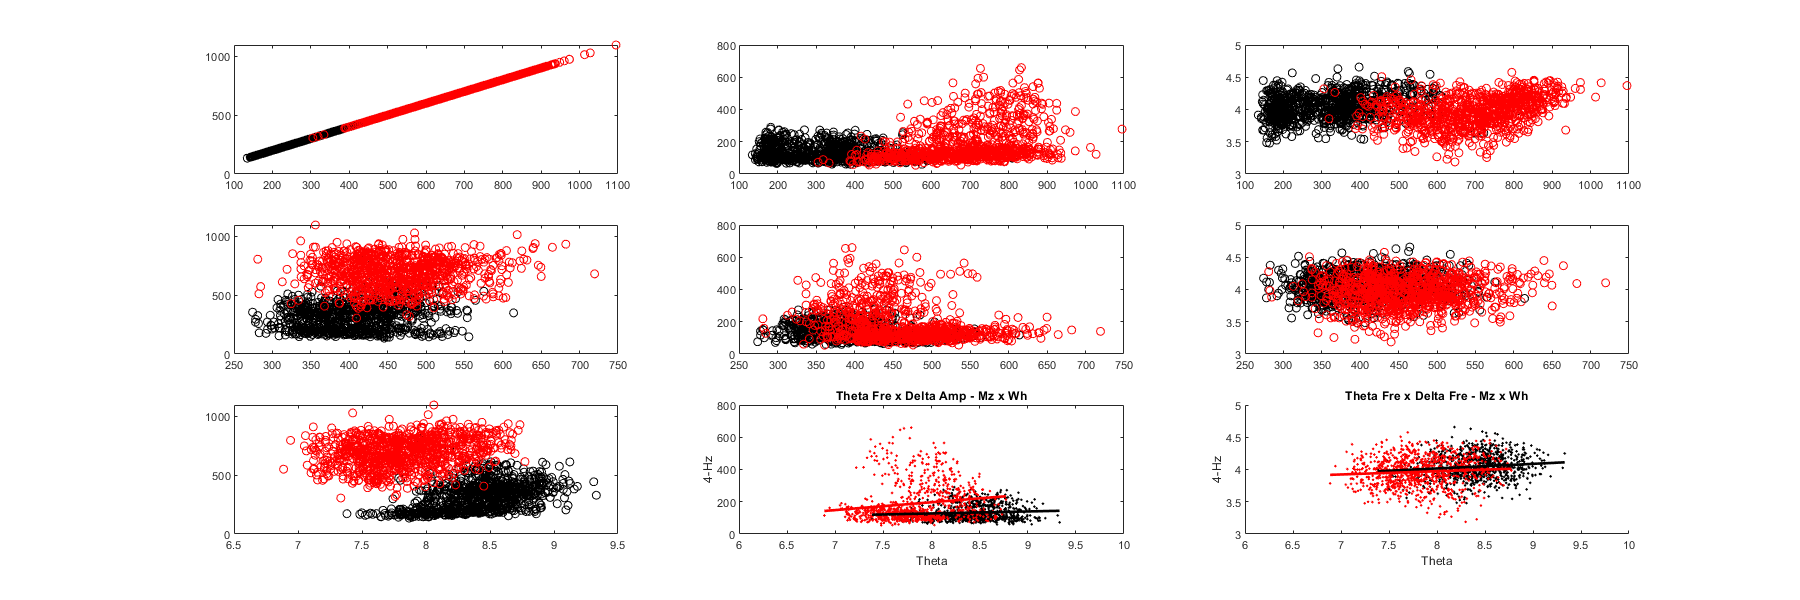

% Amp Theta x Amp Delta
fig = figure(1); clf
subplot(3,3,1)
% Speed x Speed
plot(binsResp.Speed.Th.Mz, binsResp.Speed.Dt.Mz, 'ok', binsResp.Speed.Th.Wh, binsResp.Speed.Dt.Wh, 'or')
subplot(3,3,2)
plot(binsResp.Speed.Th.Mz, binsResp.Amp.Dt.Mz, 'ok', binsResp.Speed.Th.Wh, binsResp.Amp.Dt.Wh, 'or')
subplot(3,3,3)
plot(binsResp.Speed.Th.Mz, binsResp.Fre.Dt.Mz, 'ok', binsResp.Speed.Th.Wh, binsResp.Fre.Dt.Wh, 'or')
subplot(3,3,4)
% Speed x Speed
plot(binsResp.Amp.Th.Mz, binsResp.Speed.Dt.Mz, 'ok', binsResp.Amp.Th.Wh, binsResp.Speed.Dt.Wh, 'or')
subplot(3,3,5)
plot(binsResp.Amp.Th.Mz, binsResp.Amp.Dt.Mz, 'ok', binsResp.Amp.Th.Wh, binsResp.Amp.Dt.Wh, 'or')
subplot(3,3,6)
plot(binsResp.Amp.Th.Mz, binsResp.Fre.Dt.Mz, 'ok', binsResp.Amp.Th.Wh, binsResp.Fre.Dt.Wh, 'or')
subplot(3,3,7)
% Speed x Speed
plot(binsResp.Fre.Th.Mz, binsResp.Speed.Dt.Mz, 'ok', binsResp.Fre.Th.Wh, binsResp.Speed.Dt.Wh, 'or')
subplot(3,3,8)
plotScatterNCorr(binsResp.Fre.Th.Mz, binsResp.Amp.Dt.Mz, binsResp.Fre.Th.Wh, binsResp.Amp.Dt.Wh, 0, [0, 5], [6, 10],...
    [], 'Theta Fre x Delta Amp - Mz x Wh', 'Theta', '4-Hz', 1.5)
subplot(3,3,9)
plotScatterNCorr(binsResp.Fre.Th.Mz, binsResp.Fre.Dt.Mz, binsResp.Fre.Th.Wh, binsResp.Fre.Dt.Wh, 0, [0, 5], [6, 10],...
    [], 'Theta Fre x Delta Fre - Mz x Wh', 'Theta', '4-Hz', 1.5)
set(gca, 'Box', 'off')
coefMzAmp = polyfit(binsResp.Amp.Th.Mz,  binsResp.Amp.Dt.Mz, 1)

[r, p] = corr(binsResp.Amp.Th.Mz', binsResp.Amp.Dt.Mz', 'Type', 'Spearman')

coefMzAmp =    -0.2595  238.5529


coefMzAmp = polyfit(binsResp.Amp.Th.Wh,  binsResp.Amp.Dt.Wh, 1)

r = -0.3076

p = 3.7147e-20

[r, p] = corr(binsResp.Amp.Th.Wh', binsResp.Amp.Dt.Wh', 'Type', 'Spearman')

coefMzAmp =    -0.5142  425.9305


r = -0.2843

p = 3.1358e-18

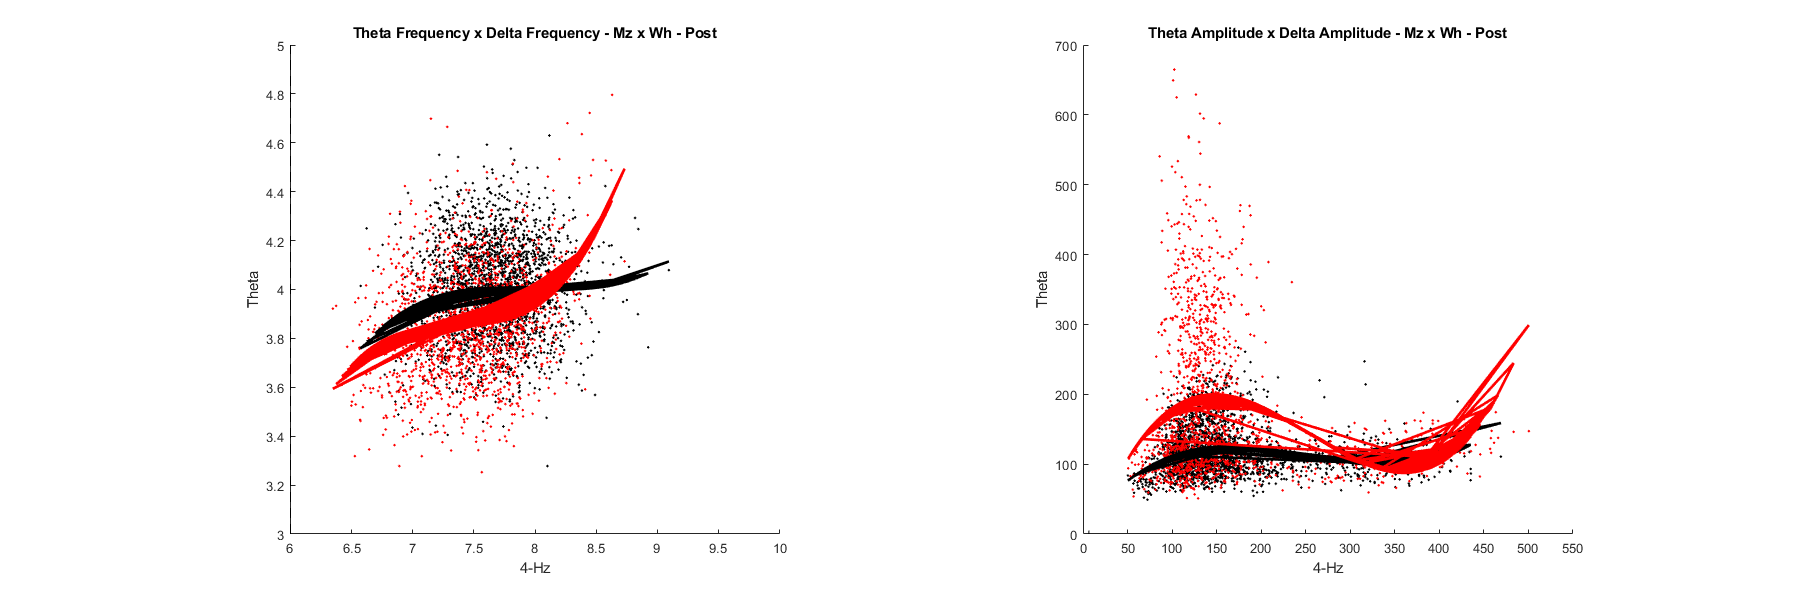

clf
fig = figure(1);
subplot(1,2,1)
plotScatterNCorr(binsResp.Fre.Th.Mz, binsResp.Fre.Dt.Mz, binsResp.Fre.Th.Wh, binsResp.Fre.Dt.Wh, 6, [0, 5], [6, 10],...
    [3, 5], 'Theta Frequency x Delta Frequency - Mz x Wh - Post', '4-Hz', 'Theta', 1.5)
axis 'square'
set(gca, 'Box', 'off')
subplot(1,2,2)
plotScatterNCorr(binsResp.Amp.Th.Mz, binsResp.Amp.Dt.Mz, binsResp.Amp.Th.Wh, binsResp.Amp.Dt.Wh, 6, [0, 5], [0, 550],...
    [0], 'Theta Amplitude x Delta Amplitude - Mz x Wh - Post', '4-Hz', 'Theta', 1.5)
axis 'square'
set(gca, 'Box', 'off')
coefMzAmp = polyfit(binsResp.Amp.Th.Wh,  binsResp.Amp.Dt.Wh, 1)

[r, p] = corr(binsResp.Amp.Th.Wh', binsResp.Amp.Dt.Wh', 'Type', 'Spearman')

coefMzAmp =    -0.2555  220.1330


coefMzAmp = polyfit(binsResp.Amp.Th.Mz,  binsResp.Amp.Dt.Mz, 1)

r = -0.0440

p = 0.0846

[r, p] = corr(binsResp.Amp.Th.Mz', binsResp.Amp.Dt.Mz', 'Type', 'Spearman')

coefMzAmp =    -0.0366  124.0579


r = 9.4809e-04

p = 0.9645

coefMzFre = polyfit(binsResp.Fre.Th.Wh,  binsResp.Fre.Dt.Wh, 1)
[r, p] = corr(binsResp.Fre.Th.Wh', binsResp.Fre.Dt.Wh', 'Type', 'Spearman')

coefMzFre =     0.1276    2.9140


coefMzFre = polyfit(binsResp.Fre.Th.Mz,  binsResp.Fre.Dt.Mz, 1)

r = 0.1903

p = 5.6939e-14

[r, p] = corr(binsResp.Fre.Th.Mz', binsResp.Fre.Dt.Mz', 'Type', 'Spearman')

coefMzFre =     0.0427    3.6703


r = 0.0648

p = 0.0023

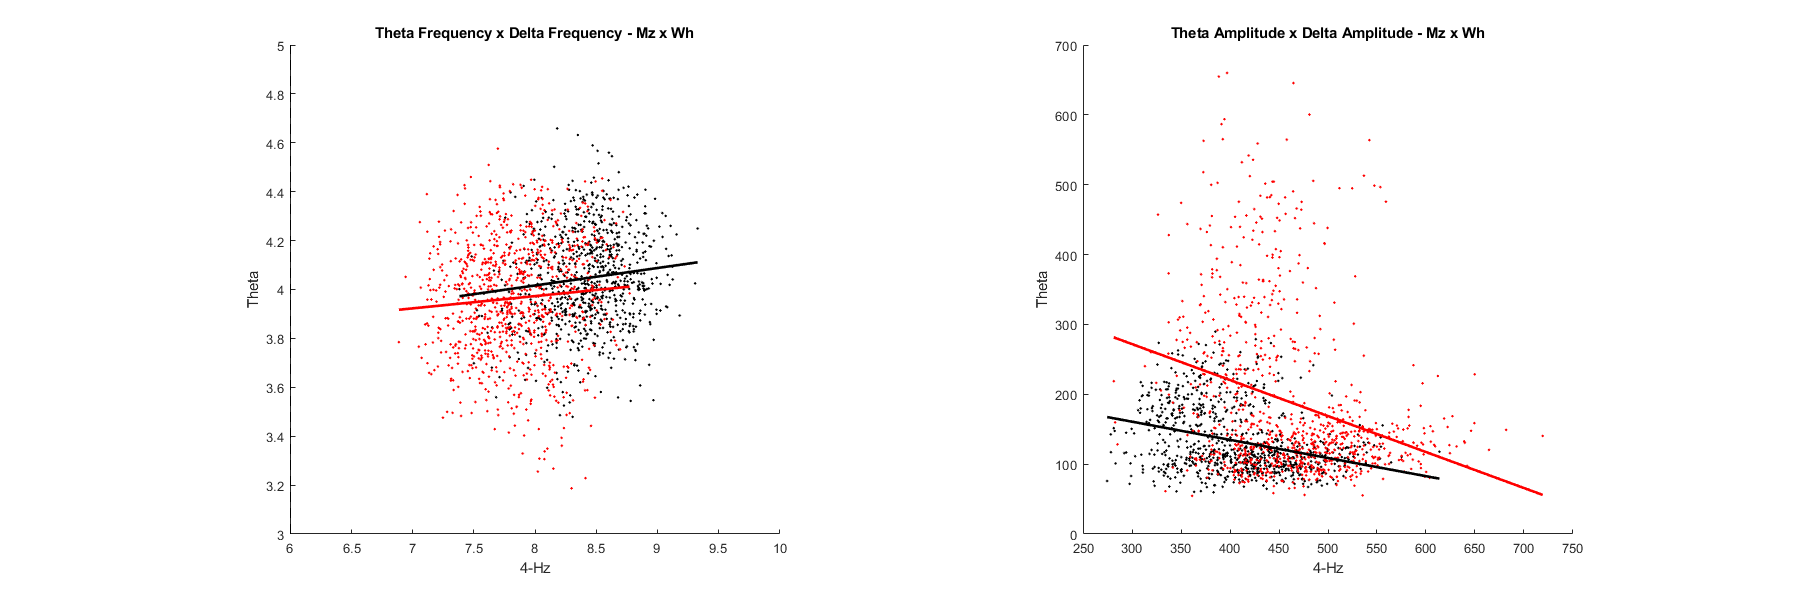

% Save plot
savePath = "H:\.shortcut-targets-by-id\1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_\ProjetoWheelMaze\Resultados\EPS Ivan\Ultima abordagem(Flow - Trial)\";
fileName = "Theta_Delta_Amp_Fre";
save = 0;
if save
    saveFile = sprintf('%s%s', savePath, fileName);
    saveas(fig, saveFile, 'epsc');
    saveas(fig, saveFile, 'png');
end
 

coefMzAmp = polyfit(binsResp.Fre.Th.Mz,  binsResp.Fre.Dt.Mz, 1)
[r, p] = corr(binsResp.Fre.Th.Mz', binsResp.Fre.Dt.Mz', 'Type', 'Spearman')

coefMzAmp =     0.0712    3.4469


coefMzAmp = polyfit(binsResp.Fre.Th.Wh,  binsResp.Fre.Dt.Wh, 1)

r = 0.1130

p = 9.4348e-04

[r, p] = corr(binsResp.Fre.Th.Wh', binsResp.Fre.Dt.Wh', 'Type', 'Spearman')

coefMzAmp =     0.0501    3.5723


r = 0.1000

p = 0.0026


dataDelta = {[], []};
dataTheta = {[], []};

for n=1:numSubReads
    dataTemp = dataFull{1,n};
    for i=1:size(dataTemp.Choice, 1)
        mzMask = dataTemp.Speed.Mz{i} > 100;
        dataDelta{1} = [dataDelta{1}, dataTemp.Delta.Amplitude{i}(mzMask)];
        dataTheta{1} = [dataTheta{1}, dataTemp.Theta.Amplitude{i}(mzMask)];
        
        whMask = dataTemp.Speed.Wh{i} > 100;
        dataDelta{2} = [dataDelta{2}, dataTemp.Delta.Amplitude{i}(whMask)];
        dataTheta{2} = [dataTheta{2}, dataTemp.Theta.Amplitude{i}(whMask)];
    end
end

dtDelta = {[], []};
for i=1:6250:(length(dataDelta{1})-6250)
    dtDelta{1} = [dtDelta{1}, mean(dataDelta{1}(i: i+6250))];
end
for i=1:6250:(length(dataDelta{2})-6250)
    dtDelta{2} = [dtDelta{2}, mean(dataDelta{2}(i: i+6250))];
end

dtTheta = {[], []};
for i=1:6250:(length(dataTheta{1})-6250)
    dtTheta{1} = [dtTheta{1},  mean(dataTheta{1}(i: i+6250))];
end
for i=1:6250:(length(dataTheta{2})-6250)
    dtTheta{2} = [dtTheta{2},  mean(dataTheta{2}(i: i+6250))];
end

[rho,pval] = corr(dtDelta{1}', dtTheta{1}','Type','Spearman');
rho,pval
[rho,pval] = corr(dtDelta{2}', dtTheta{2}','Type','Spearman');

rho = -0.3076

pval = 3.7147e-20

rho,pval

rho = -0.2843

pval = 3.1358e-18

fig = figure(5); clf
fig.Position = [0,0, 1600, 800];
sgtitle('Amplitude')
subplot(1,2,1)
plot(dtDelta{1}, dtTheta{1}, 'ko', 'markersize', 1.5)
hold on
coefMzAmp = polyfit(dtDelta{1},  dtTheta{1}, 1);
coefMzAmp
plot(dtDelta{1}, polyval(coefMzAmp, dtDelta{1}),'k-','linewidth',2)
hold off
axis square
title('Maze')

subplot(1,2,2)
plot(dtDelta{2}, dtTheta{2}, 'ro', 'markersize', 1.5)
hold on
coefMzAmp = polyfit(dtDelta{2},  dtTheta{2}, 1); 
coefMzAmp
plot(dtDelta{2}, polyval(coefMzAmp, dtDelta{2}),'r-','linewidth',2)
axis square
title('Wheel')

dataDelta = {[], []};
dataTheta = {[], []};

for n=1:numSubReads
    dataTemp = dataFull{1,n};
    for i=1:size(dataTemp.Choice, 1)
        mzMask = dataTemp.Speed.Mz{i} > 100;
        dataDelta{1} = [dataDelta{1}, dataTemp.Delta.InstFreq{i}(mzMask)];
        dataTheta{1} = [dataTheta{1}, dataTemp.Theta.InstFreq{i}(mzMask)];
        
        whMask = dataTemp.Speed.Wh{i} > 100;
        dataDelta{2} = [dataDelta{2}, dataTemp.Delta.InstFreq{i}(whMask)];
        dataTheta{2} = [dataTheta{2}, dataTemp.Theta.InstFreq{i}(whMask)];
    end
end

dtDelta = {[], []};
for i=1:6250:(length(dataDelta{1})-6250)
    dtDelta{1} = [dtDelta{1}, mean(dataDelta{1}(i: i+6250))];
end
for i=1:6250:(length(dataDelta{2})-6250)
    dtDelta{2} = [dtDelta{2}, mean(dataDelta{2}(i: i+6250))];
end

dtTheta = {[], []};
for i=1:6250:(length(dataTheta{1})-6250)
    dtTheta{1} = [dtTheta{1},  mean(dataTheta{1}(i: i+6250))];
end
for i=1:6250:(length(dataTheta{2})-6250)
    dtTheta{2} = [dtTheta{2},  mean(dataTheta{2}(i: i+6250))];
end

[rho,pval] = corr(dtDelta{1}', dtTheta{1}','Type','Spearman');
rho,pval
[rho,pval] = corr(dtDelta{2}', dtTheta{2}','Type','Spearman');

rho = 0.1130

pval = 9.4348e-04

rho,pval

rho = 0.1000

pval = 0.0026

fig = figure(5); clf
fig.Position = [0,0, 1600, 800];
sgtitle('Inst. Frequency')
subplot(1,2,1)
plot(dtDelta{1}, dtTheta{1}, 'ko', 'markersize', 1.5)
hold on
coefMzAmp = polyfit(dtDelta{1},  dtTheta{1}, 1); 
coefMzAmp
plot(dtDelta{1}, polyval(coefMzAmp, dtDelta{1}),'k-','linewidth',2)

coefMzAmp =     0.1930    7.6395


hold off
axis square
title('Maze')

subplot(1,2,2)
plot(dtDelta{2}, dtTheta{2}, 'ro', 'markersize', 1.5)
hold on
coefMzAmp = polyfit(dtDelta{2},  dtTheta{2}, 1); 
coefMzAmp
plot(dtDelta{2}, polyval(coefMzAmp, dtDelta{2}),'r-','linewidth',2)

coefMzAmp =     0.1215    7.3494


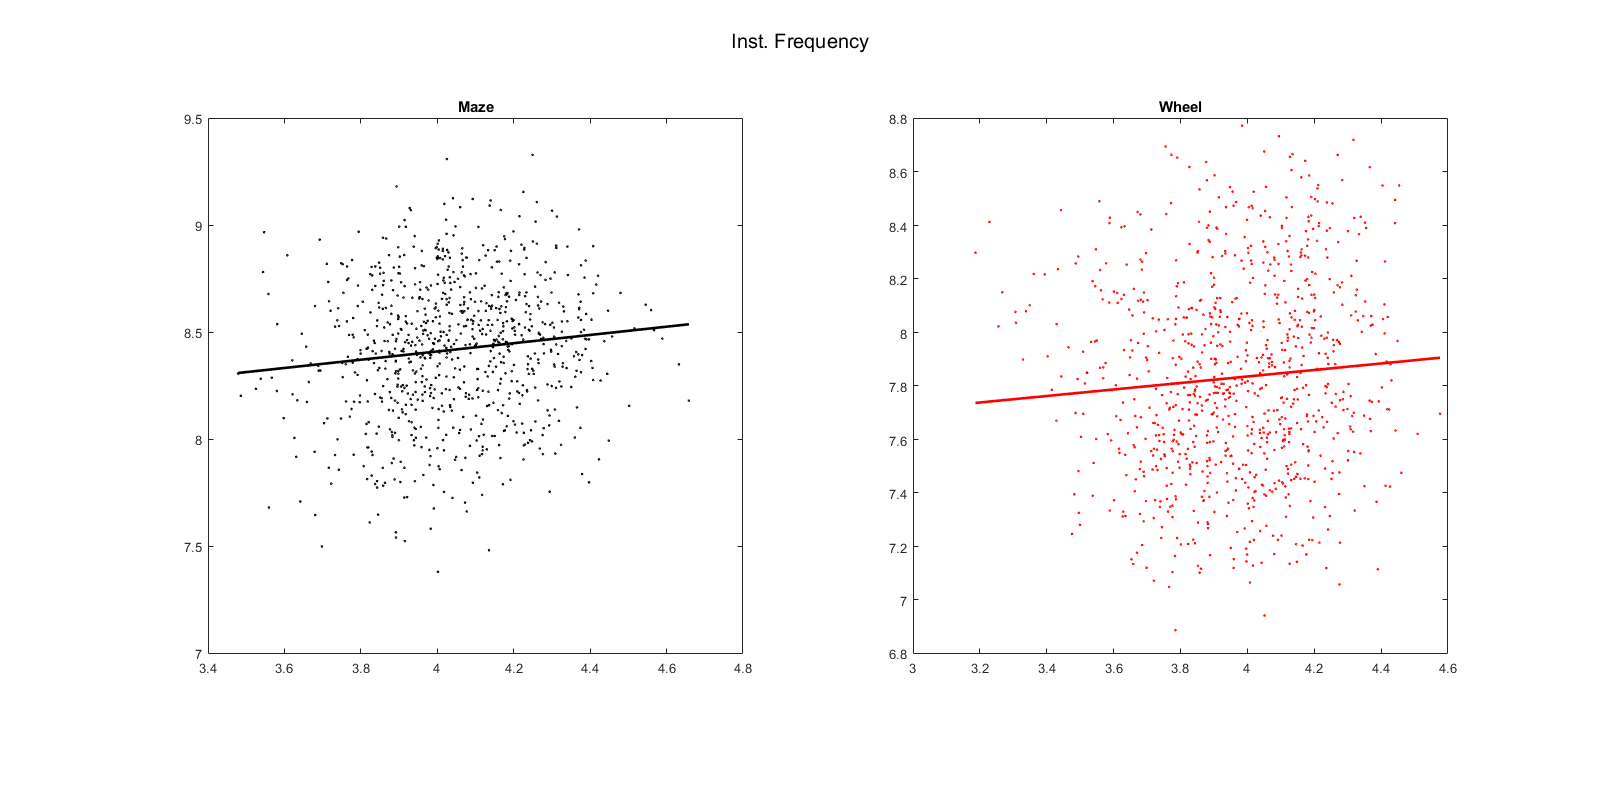

axis square
title('Wheel')

% SpeedMzE = [];SpeedMzC = [];
% SpeedWhE = [];SpeedWhC = [];
% DtAmpMzE = [];DtAmpMzC = [];
% DtAmpWhE = [];DtAmpWhC = [];
% DtFreMzE = [];DtFreMzC = [];
% DtFreWhE = [];DtFreWhC = [];
% % iSpeedMz = [];
% % iSpeedWh = [];
% % iDtAmpMz = [];
% % iDtAmpWh = [];
% % iDtFreMz = [];
% % iDtFreWh = [];
% for f=1:10
%     dataSingle = dataFull{1,f};
%     speedthresh = 150;
%     for l=unique(dataSingle.Band.Lap)'
%         clear maskLap maskMzSpeed maskWhSpeed 
%         maskLap     = dataSingle.Band.Lap==l;
%         maskLapErr  = dataSingle.Band.Choice==0;
%         maskLapCor  = dataSingle.Band.Choice==1;
%         maskMzSpeed = dataSingle.Band.MzSpeed>100;
%         maskWhSpeed = dataSingle.Band.WhSpeed>100;
%        
%         %SPD AMP FRE: TRIAL BY TRIAL
%         SpeedMzE      = [SpeedMzE, mean(dataSingle.Band.MzSpeed(maskLap & maskMzSpeed & maskLapErr))];
%         SpeedWhE      = [SpeedWhE, mean(dataSingle.Band.WhSpeed(maskLap & maskWhSpeed & maskLapErr))];
%         DtAmpMzE      = [DtAmpMzE, mean(dataSingle.Band.Amplitude(maskLap & maskMzSpeed & maskLapErr))];
%         DtAmpWhE      = [DtAmpWhE, mean(dataSingle.Band.Amplitude(maskLap & maskWhSpeed & maskLapErr))];
%         DtFreMzE      = [DtFreMzE, mean(dataSingle.Band.InstFreq(maskLap & maskMzSpeed & maskLapErr))];
%         DtFreWhE      = [DtFreWhE, mean(dataSingle.Band.InstFreq(maskLap & maskWhSpeed & maskLapErr))];
%         SpeedMzC      = [SpeedMzC, mean(dataSingle.Band.MzSpeed(maskLap & maskMzSpeed & maskLapCor))];
%         SpeedWhC      = [SpeedWhC, mean(dataSingle.Band.WhSpeed(maskLap & maskWhSpeed & maskLapCor))];
%         DtAmpMzC      = [DtAmpMzC, mean(dataSingle.Band.Amplitude(maskLap & maskMzSpeed & maskLapCor))];
%         DtAmpWhC      = [DtAmpWhC, mean(dataSingle.Band.Amplitude(maskLap & maskWhSpeed & maskLapCor))];
%         DtFreMzC      = [DtFreMzC, mean(dataSingle.Band.InstFreq(maskLap & maskMzSpeed & maskLapCor))];
%         DtFreWhC      = [DtFreWhC, mean(dataSingle.Band.InstFreq(maskLap & maskWhSpeed & maskLapCor))];
%     end
% end    

%Mz
SpdMzE = SpeedMzE(~isnan(SpeedMzE));
SpdMzC = SpeedMzC(~isnan(SpeedMzC));
AmpMzE = DtAmpMzE(~isnan(DtAmpMzE));
AmpMzC = DtAmpMzC(~isnan(DtAmpMzC));
FreMzE = DtFreMzE(~isnan(DtFreMzE));
FreMzC = DtFreMzC(~isnan(DtFreMzC));
%Wh
SpdWhE = SpeedWhE(~isnan(SpeedWhE));
SpdWhC = SpeedWhC(~isnan(SpeedWhC));
AmpWhE = DtAmpWhE(~isnan(DtAmpWhE));
AmpWhC = DtAmpWhC(~isnan(DtAmpWhC));
FreWhE = DtFreWhE(~isnan(DtFreWhE));
FreWhC = DtFreWhC(~isnan(DtFreWhC));

%%
%Mz
p=swtest([SpdMzE,SpdMzC]);
if p==1
    [p_SpeedMz, h_SpeedMz]=ranksum(SpdMzE,SpdMzC);
else
    [h_SpeedMz, p_SpeedMz]=ttest(SpdMzE,SpdMzC);
end

p=swtest([AmpMzE,AmpMzC]);
if p==1
    [p_AmpMz, h_AmpMz]=ranksum(AmpMzE,AmpMzC);
else
    [h_AmpMz, p_AmpMz]=ttest(AmpMzE,AmpMzC);
end

p=swtest([FreMzE,FreMzC]);
if p==1
    [p_FreMz, h_FreMz]=ranksum(FreMzE,FreMzC);
else
    [h_FreMz, p_FreMz]=ttest(FreMzE,FreMzC);
end

% Wh
p=swtest([SpdWhE,SpdWhC]);
if p==1
    [p_SpeedWh, h_SpeedWh]=ranksum(SpdWhE,SpdWhC);
else
    [h_SpeedWh, p_SpeedWh]=ttest(SpdWhE,SpdWhC);
end

p=swtest([AmpWhE,AmpWhC]);
if p==1
    [p_AmpWh, h_AmpWh]=ranksum(AmpWhE,AmpWhC);
else
    [h_AmpWh, p_AmpWh]=ttest(AmpWhE,AmpWhC);
end

p=swtest([FreWhE,FreWhC]);
if p==1
    [p_FreWh, h_FreWh]=ranksum(FreWhE,FreWhC);
else
    [h_FreWh, p_FreWh]=ttest2(FreWhE,FreWhC);
end

%% Mz
figure(10),clf

%histograms
subplot(231)
bins=[0:30:1000];
    % SpeedAll=[];
histogram(SpdMzC,bins,'FaceColor',[0 1 0])
hold on
histogram(SpdMzE,bins,'FaceColor',[1 0 0])
plot([speedthresh speedthresh],[0 100],'k--')
xlim([0 1000])
xlabel 'Speed (cm/s)'
ylabel 'Count (#)'
title 'Performance Speed'
box off
axis square
set(gcf,'color','w')

subplot(232)
bins=[0:20:500];
histogram(AmpMzC,bins,'FaceColor',[0 1 0])
hold on
histogram(AmpMzE,bins,'FaceColor',[1 0 0])
xlim([50 500])
xlabel 'Amplitude (mV)'
ylabel 'Count (#)'
title '4-Hz Amplitude'
box off
axis square

subplot(233)
bins=[3:0.05:5];
histogram(FreMzC,bins,'FaceColor',[0 1 0])
hold on
histogram(FreMzE,bins,'FaceColor',[1 0 0])
xlim([3.5 4.5])
xlabel 'Frequency (Hz)'
ylabel 'Count (#)'
title 'Frequency'
box off
axis square

%boxplot
subplot(234)
C = [SpdMzE SpdMzC];
grp = [zeros(size(SpdMzE)),ones(size(SpdMzC))];
boxplot(C,grp)
hold on
text(1,450,num2str(p_SpeedMz))
xlim([0 3])
xlabel 'Incorrect x Correct'
ylabel 'Speed (cm/s)'
title 'Speed'
box off
axis square
set(gcf,'color','w')

subplot(235)
C = [AmpMzE AmpMzC];
grp = [zeros(size(AmpMzE)),ones(size(AmpMzC))];
boxplot(C,grp)
hold on
text(1,200,num2str(p_AmpMz))
xlim([0 3])
xlabel 'Incorrect x Correct'
ylabel 'Amplitude (mV)'
title '4-Hz Amplitude'
box off
axis square

subplot(236)
C = [FreMzE FreMzC];
grp = [zeros(size(FreMzE)),ones(size(FreMzC))];
boxplot(C,grp)
text([1],[4.4],num2str(p_FreMz))
ylim([3.5 4.5])
xlim([0 3])
xlabel 'Incorrect x Correct'
ylabel 'Frequency (Hz)'
title 'Frequency'
box off
axis square

%% Wh
figure(11),clf

%histograms
subplot(231)
bins=[0:30:1000];
    % SpeedAll=[];
histogram(SpdWhC,bins,'FaceColor',[0 1 0])
hold on
histogram(SpdWhE,bins,'FaceColor',[1 0 0])
plot([speedthresh speedthresh],[0 100],'k--')
xlim([0 1000])
xlabel 'Speed (cm/s)'
ylabel 'Count (#)'
title 'Performance Speed'
box off
axis square
set(gcf,'color','w')

subplot(232)
bins=[0:20:500];
histogram(AmpWhC,bins,'FaceColor',[0 1 0])
hold on
histogram(AmpWhE,bins,'FaceColor',[1 0 0])
xlim([50 500])
xlabel 'Amplitude (mV)'
ylabel 'Count (#)'
title '4-Hz Amplitude'
box off
axis square

subplot(233)
bins=[3:0.05:5];
histogram(FreWhC,bins,'FaceColor',[0 1 0])
hold on
histogram(FreWhE,bins,'FaceColor',[1 0 0])
xlim([3.5 4.5])
xlabel 'Frequency (Hz)'
ylabel 'Count (#)'
title 'Frequency'
box off
axis square

%boxplot
subplot(234)
C = [SpdWhE SpdWhC];
grp = [zeros(size(SpdWhE)),ones(size(SpdWhC))];
boxplot(C,grp)
hold on
text(1,550,num2str(p_SpeedWh))
xlim([0 3])
xlabel 'Incorrect x Correct'
ylabel 'Speed (cm/s)'
title 'Speed'
box off
axis square
set(gcf,'color','w')

subplot(235)
C = [AmpWhE AmpWhC];
grp = [zeros(size(AmpWhE)),ones(size(AmpWhC))];
boxplot(C,grp)
hold on
text(1,400,num2str(p_AmpWh))
xlim([0 3])
xlabel 'Incorrect x Correct'
ylabel 'Amplitude (mV)'
title '4-Hz Amplitude'
box off
axis square

subplot(236)
C = [FreWhE FreWhC];
grp = [zeros(size(FreWhE)),ones(size(FreWhC))];
boxplot(C,grp)
text(1,4.4,num2str(p_FreWh))
ylim([3.5 4.5])
xlim([0 3])
xlabel 'Incorrect x Correct'
ylabel 'Frequency (Hz)'
title 'Frequency'
box off
axis square



%%